## section 1 import data and remove missing samples

import data file with import function prepared

NBI2020 = importNBIData('2020HwyBridgesDelimitedAllStates.txt');

HwyBridgesDelimitedAllStates = 475417×123 table
    STATE_CODE_001    STRUCTURE_NUMBER_008    RECORD_TYPE_005A    ROUTE_PREFIX_005B    SERVICE_LEVEL_005C    ROUTE_NUMBER_005D    DIRECTION_005E    HIGHWAY_DISTRICT_002    COUNTY_CODE_003    PLACE_CODE_004        FEATURES_DESC_006A         CRITICAL_FACILITY_006B    FACILITY_CARRIED_007             LOCATION_009             MIN_VERT_CLR_010    KILOPOINT_011    BASE_HWY_NETWORK_012    LRS_INV_ROUTE_013A    SUBROUTE_NO_013B     LAT_016       LONG_017      DETOUR_KILOS_019    TOLL_020    MAINTENANCE_021    OWNER_022    

filling missing values with standardizeMissing function

NBI2020.MAIN_UNIT_SPANS_045 = standardizeMissing(NBI2020.MAIN_UNIT_SPANS_045,[-1,0]);
%sum(ismissing(NBI2020_standadized_missing))

remove bridges with NaN feature values.

load_missing = NBI2020(isnan(NBI2020.DESIGN_LOAD_031),:);
h_missing = height(load_missing)

h_missing = 36884

h_total = height(NBI2020);
perc_missing = h_missing/h_total * 100

perc_missing = 7.7583

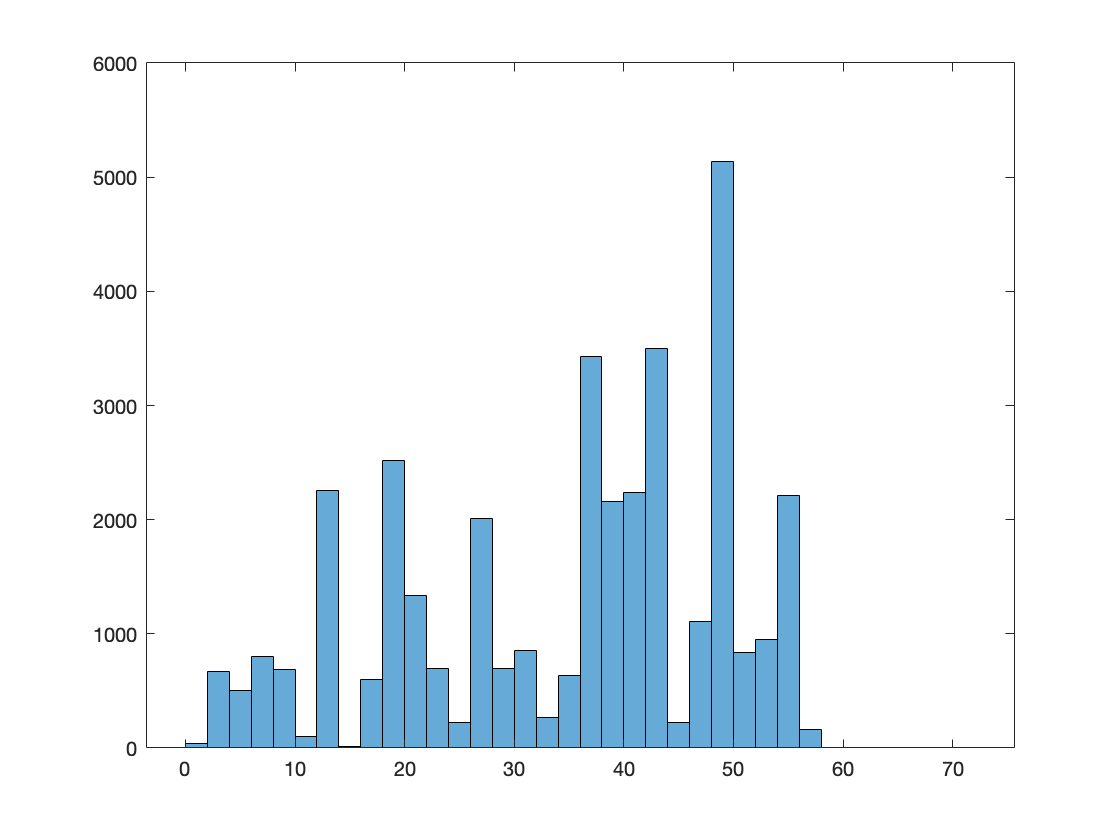


% visualizing the characteristics of samples with missing values
histogram(load_missing.STATE_CODE_001)

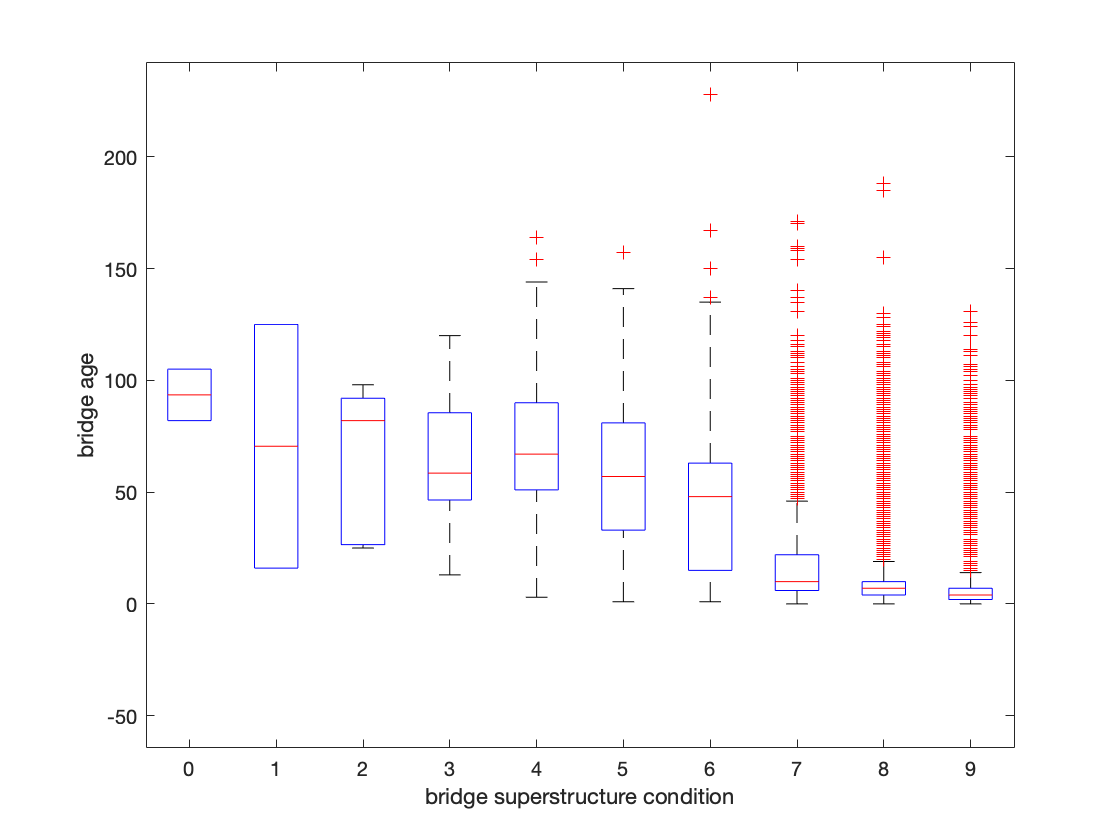

boxplot(load_missing.AGE,load_missing.SUPERSTRUCTURE_COND_059)
xlabel("bridge superstructure condition")
ylabel("bridge age")

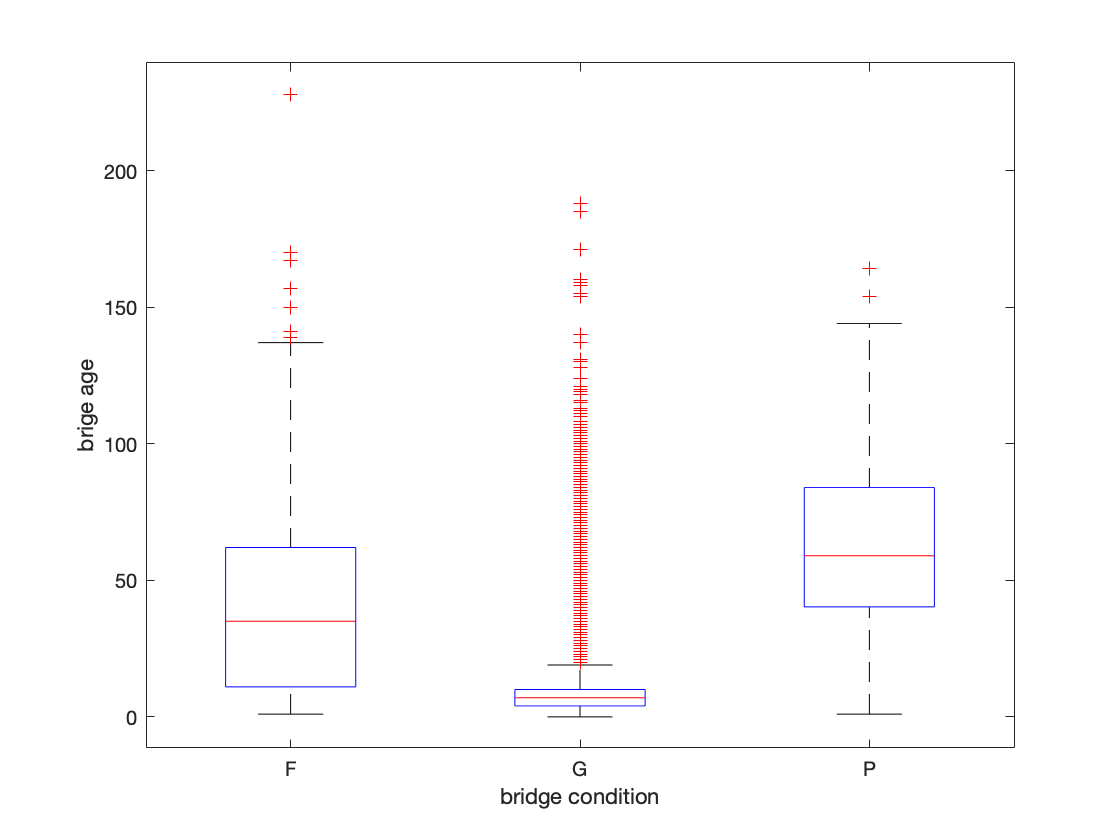

boxplot(load_missing.AGE,load_missing.BRIDGE_CONDITION)
xlabel("bridge condition")
ylabel("brige age")


% remove samples with missing values and store left samples into NBI_rm table
NBI2020 = rmmissing(NBI2020);
h1 = height(NBI2020)

h1 = 438378

## section 2 recorgnize/remove outliers and normalize numeric features

Initial status

% make a copy of NBI2020 as inital table.
NBI2020_updated = NBI2020;

2.1 AGE feature -- numeric

recognize outliers

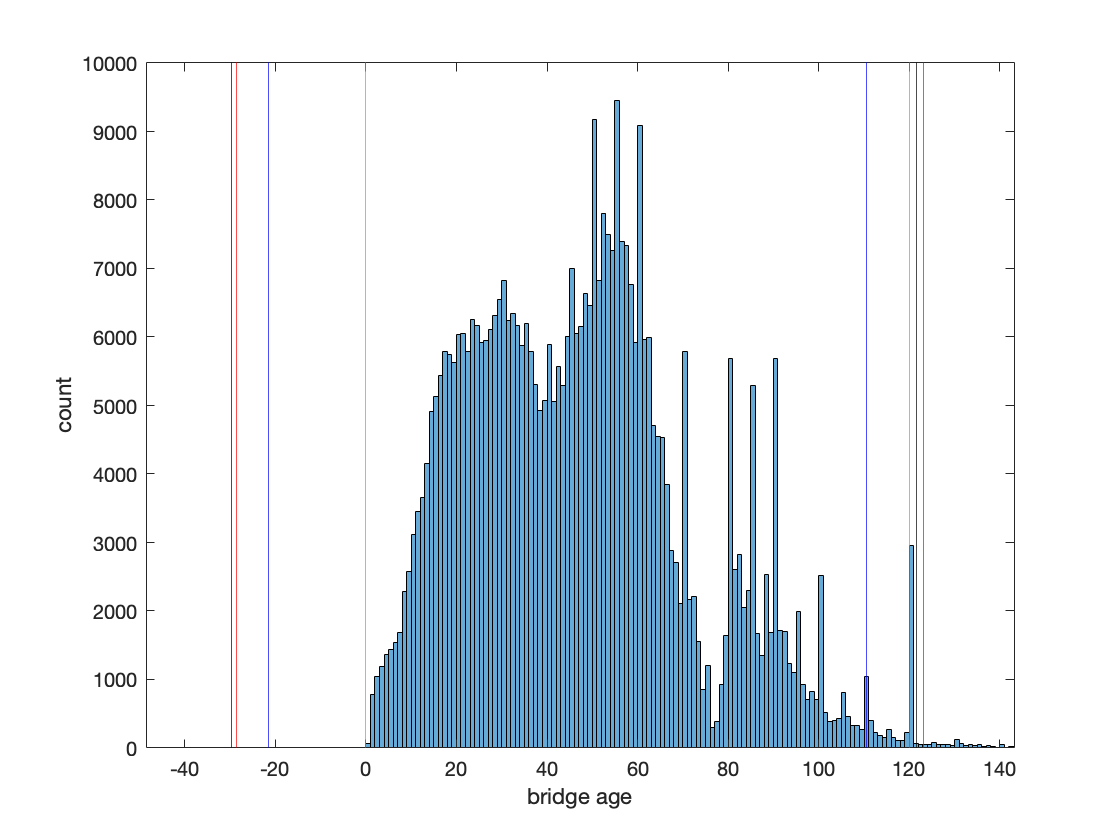

% using four methods to recognize outliers for a specific feature
[~,stdLow,stdHigh,~] = isoutlier(NBI2020_updated.AGE,"mean");  
[~,quartLow,quartHigh,~] = isoutlier(NBI2020_updated.AGE,"quartiles");  
[~,medLow,medHigh,~] = isoutlier(NBI2020_updated.AGE,"median");
[~,pLow,pHigh,~] = isoutlier(NBI2020_updated.AGE,"percentiles",[0,99]);  % choosing this method

histogram(NBI2020_updated.AGE);  
xlabel("bridge age"); 
ylabel("count");
xline(stdLow,"r"); xline(stdHigh,"r"); 
xline(quartLow,"b"); xline(quartHigh,"b"); 
xline(medLow,"k"); xline(medHigh,"k"); 
xline(pLow,"g"); xline(pHigh,"g")
% 
xlim([stdLow-20,stdHigh+20]) %optical zoom in

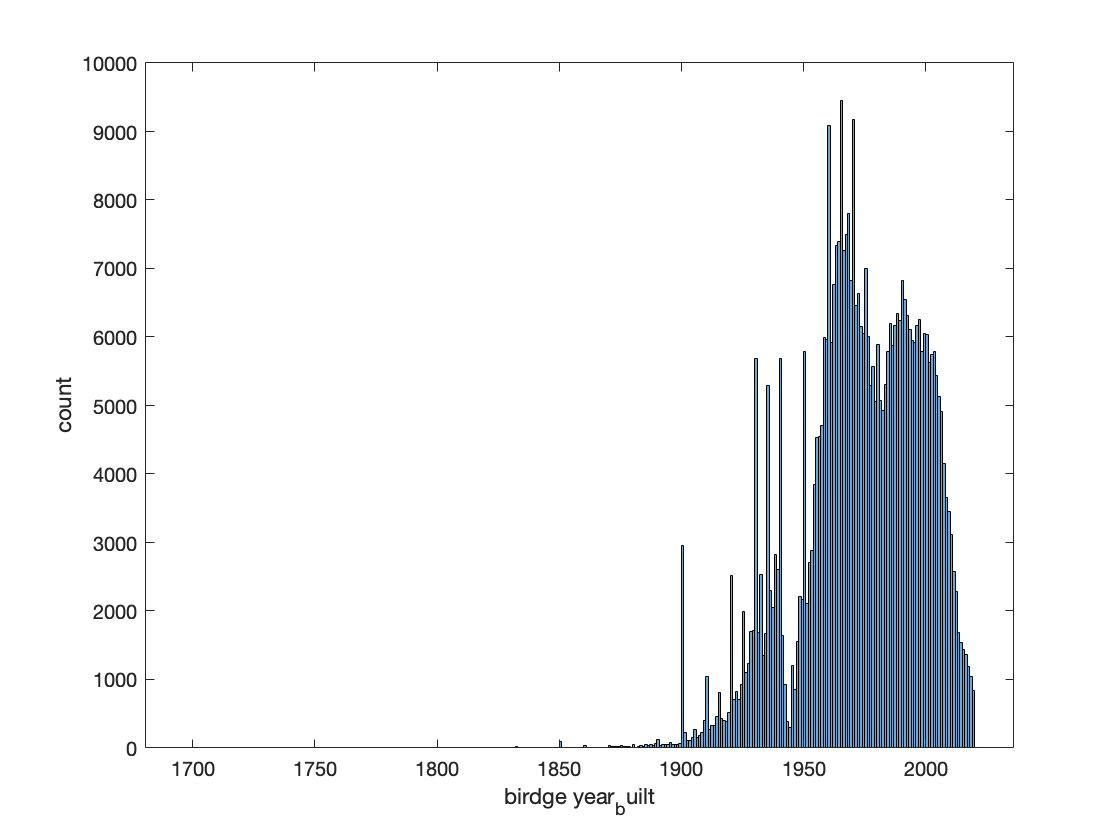

histogram(NBI2020_updated.YEAR_BUILT_027)
xlabel("birdge year_built")
ylabel("count")

removing recognized outliers -- using percentile method

h_before = height(NBI2020_updated)

h_before = 438378

NBI2020_updated = rmoutliers(NBI2020_updated,"percentiles",[0,99],"DataVariables","AGE");
h_after = height(NBI2020_updated)

h_after = 436770

h_removed = h_before - h_after  % number of samples removed in this step

h_removed = 1608

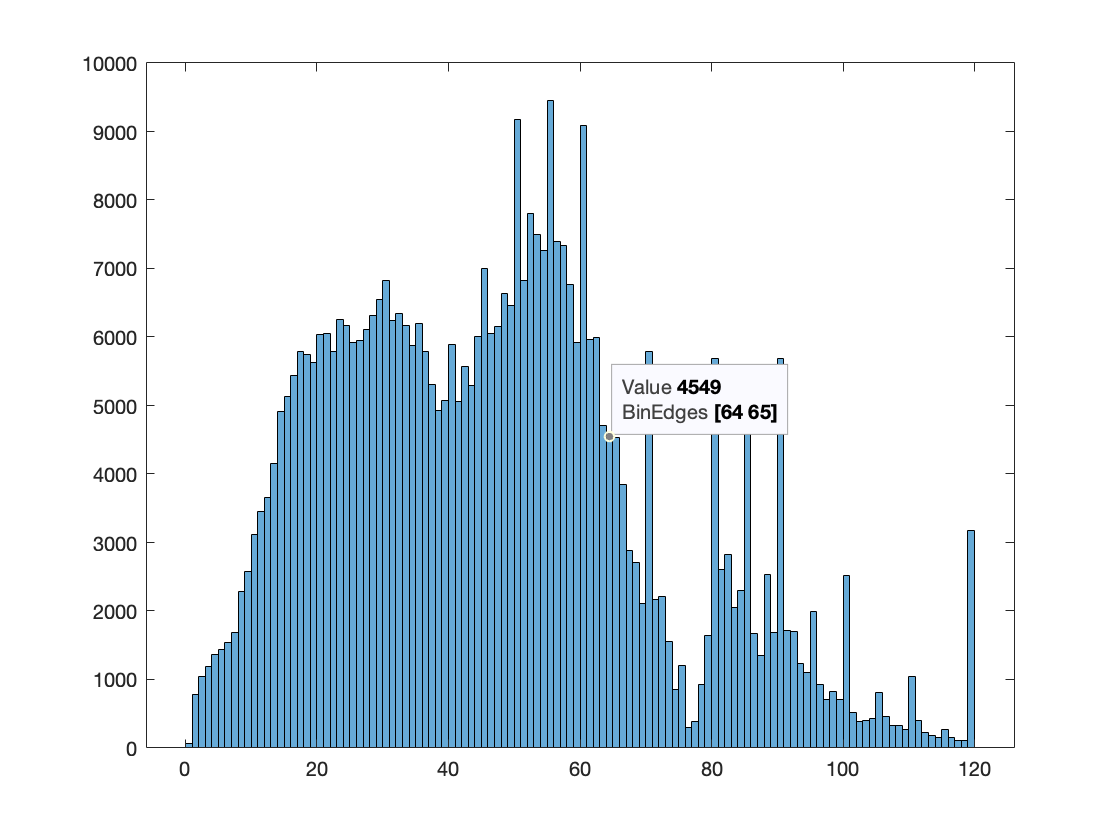

histogram(NBI2020_updated.AGE)

normalizing

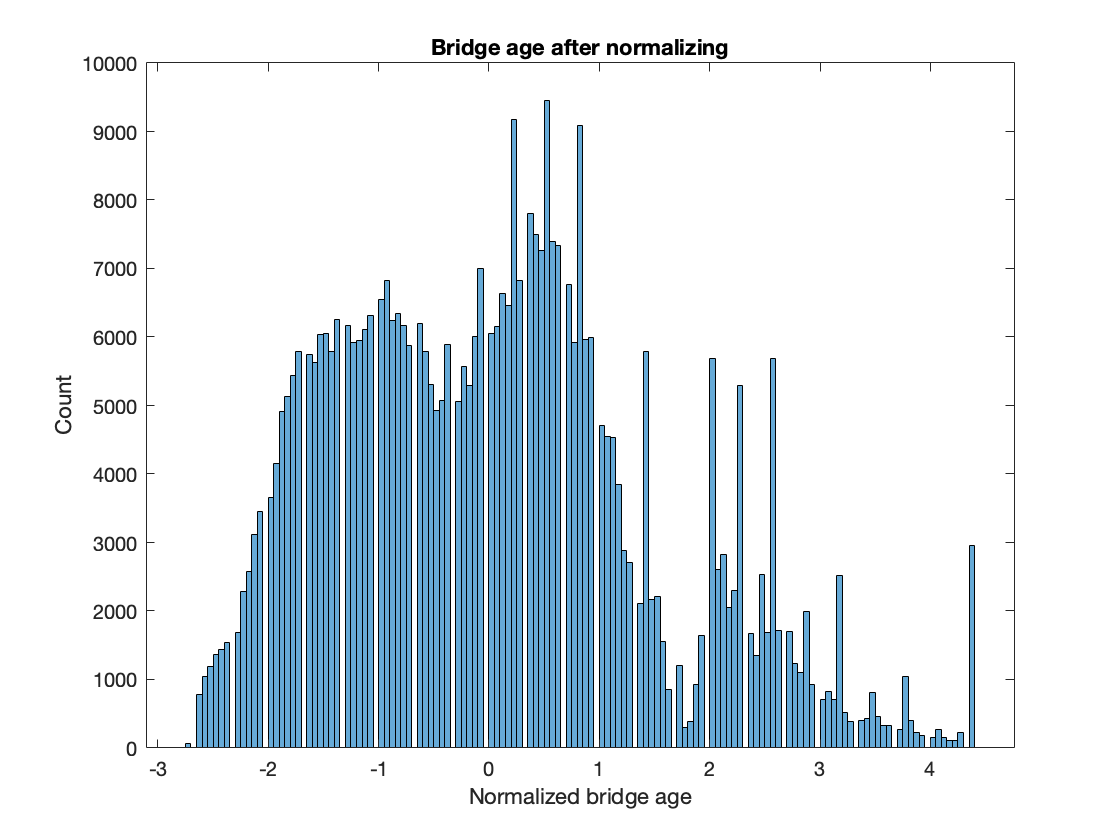

NBI2020_updated.AGE = normalize(NBI2020_updated.AGE,"zscore","robust");
histogram(NBI2020_updated.AGE)
xlabel("Normalized bridge age")
ylabel("Count")
title("Bridge age after normalizing")


height(NBI2020_updated)

ans = 436770

2.2 ADT_029 numeric

recognize outlier

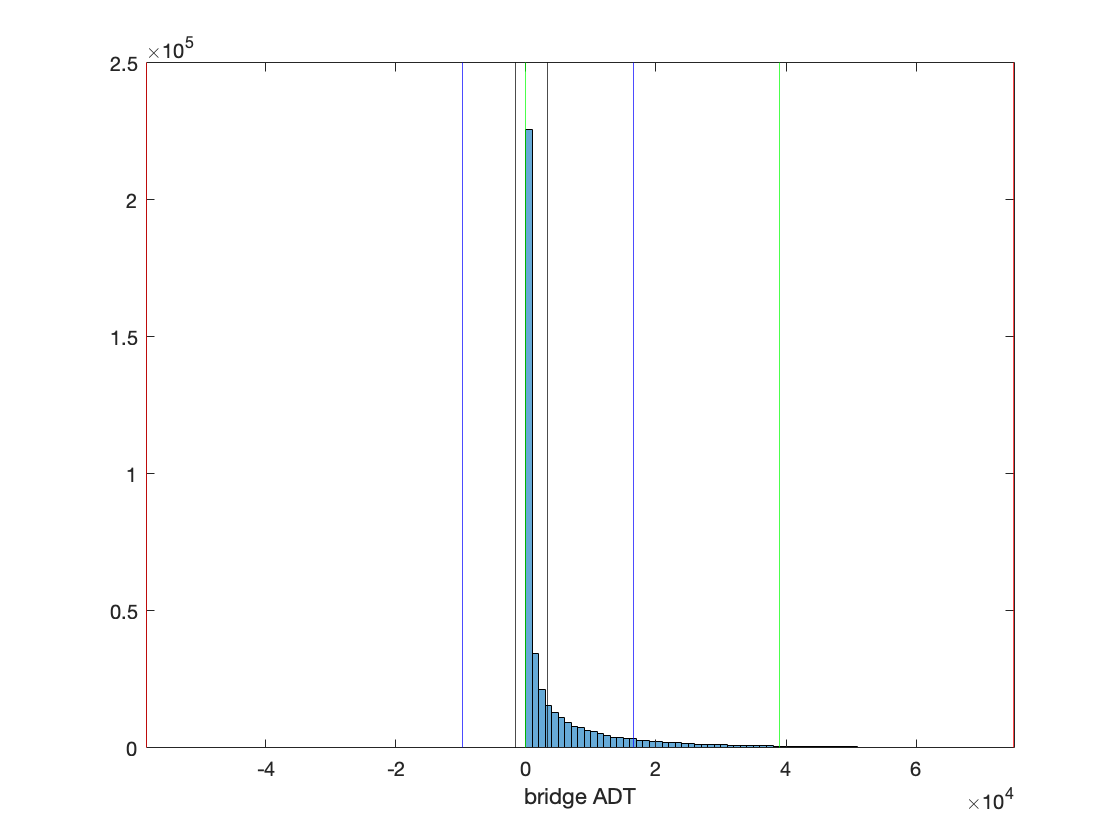

% using four methods to recognize outliers for a specific feature
[~,stdLow,stdHigh,~] = isoutlier(NBI2020_updated.ADT_029,"mean");  
[~,quartLow,quartHigh,~] = isoutlier(NBI2020_updated.ADT_029,"quartiles");  
[~,medLow,medHigh,~] = isoutlier(NBI2020_updated.ADT_029,"median","ThresholdFactor",2);
[~,pLow,pHigh,~] = isoutlier(NBI2020_updated.ADT_029,"percentiles",[0,95]);  % choosing this method

histogram(NBI2020_updated.ADT_029);  
xlabel("bridge ADT"); 
xline(stdLow,"r"); xline(stdHigh,"r"); 
xline(quartLow,"b"); xline(quartHigh,"b"); 
xline(medLow,"k"); xline(medHigh,"k");  
xline(pLow,"g"); xline(pHigh,"g")

xlim([stdLow-20,stdHigh+20]) %optical zoom in

remove outliers

h_before = height(NBI2020_updated)

h_before = 436770

NBI2020_updated = rmoutliers(NBI2020_updated,"percentiles",[0,95],"DataVariables","ADT_029");
h_after = height(NBI2020_updated)

h_after = 415002

h_removed = h_before - h_after

h_removed = 21768

normalizing

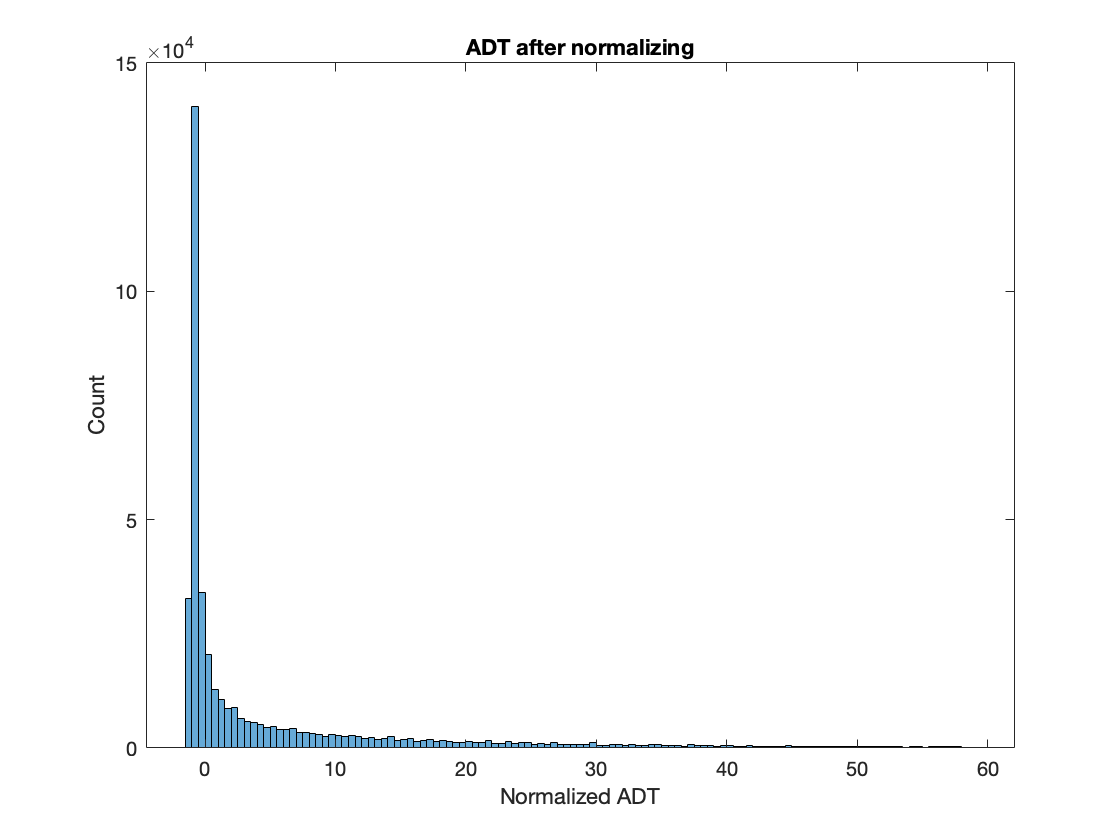

NBI2020_updated.ADT_029 = normalize(NBI2020_updated.ADT_029,"zscore","robust");
histogram(NBI2020_updated.ADT_029)
xlabel("Normalized ADT")
ylabel("Count")
title("ADT after normalizing")

2.3 MAIN_UNIT_SPANS_045 numeric

recognize outlier

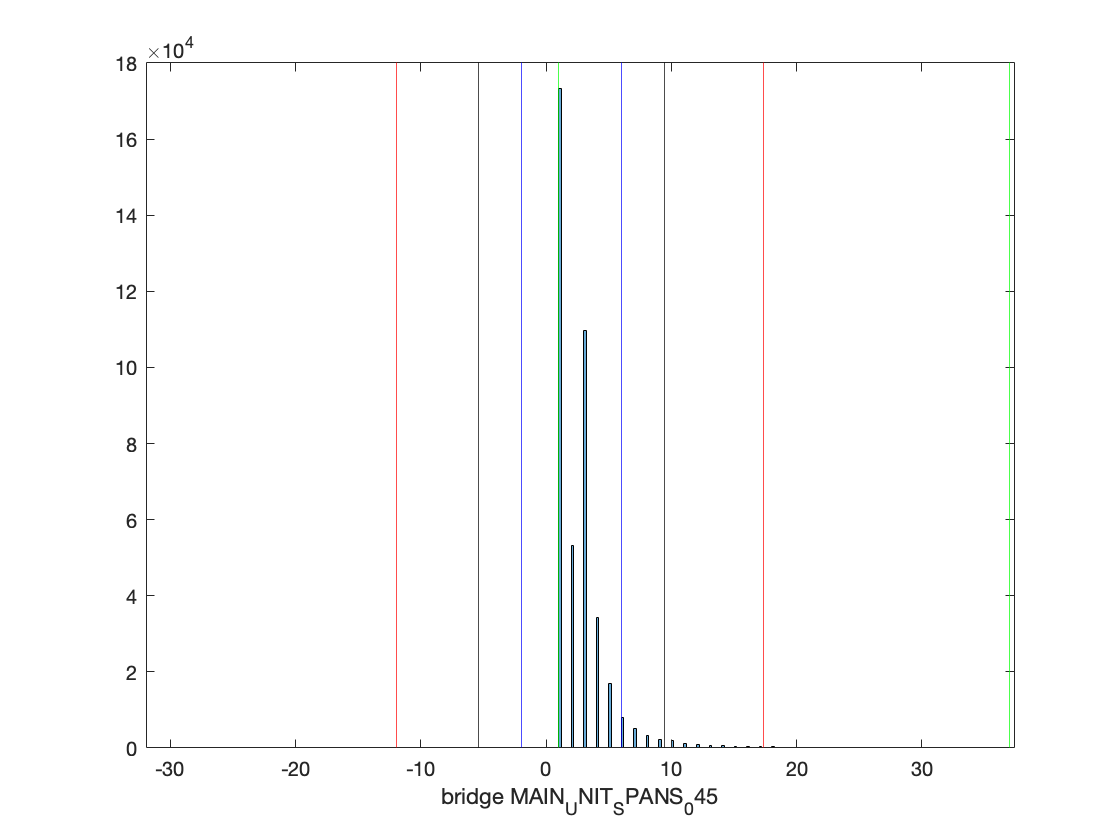

% using four methods to recognize outliers for a specific feature
[~,stdLow,stdHigh,~] = isoutlier(NBI2020_updated.MAIN_UNIT_SPANS_045,"mean");  
[~,quartLow,quartHigh,~] = isoutlier(NBI2020_updated.MAIN_UNIT_SPANS_045,"quartiles");  
[~,medLow,medHigh,~] = isoutlier(NBI2020_updated.MAIN_UNIT_SPANS_045,"median","ThresholdFactor",5);
[~,pLow,pHigh,~] = isoutlier(NBI2020_updated.MAIN_UNIT_SPANS_045,"percentiles",[0,99.9]);  % choosing this method

histogram(NBI2020_updated.MAIN_UNIT_SPANS_045);  
xlabel("bridge MAIN_UNIT_SPANS_045"); 
xline(stdLow,"r"); xline(stdHigh,"r"); 
xline(quartLow,"b"); xline(quartHigh,"b"); 
xline(medLow,"k"); xline(medHigh,"k");  
xline(pLow,"g"); xline(pHigh,"g")

xlim([stdLow-20,stdHigh+20]) %optical zoom in

remove outliers

h_before = height(NBI2020_updated)

h_before = 415002

NBI2020_updated = rmoutliers(NBI2020_updated,"percentiles",[0,99.9],"DataVariables","MAIN_UNIT_SPANS_045");
h_after = height(NBI2020_updated)

h_after = 414595

h_removed = h_before - h_after

h_removed = 407

normalizing

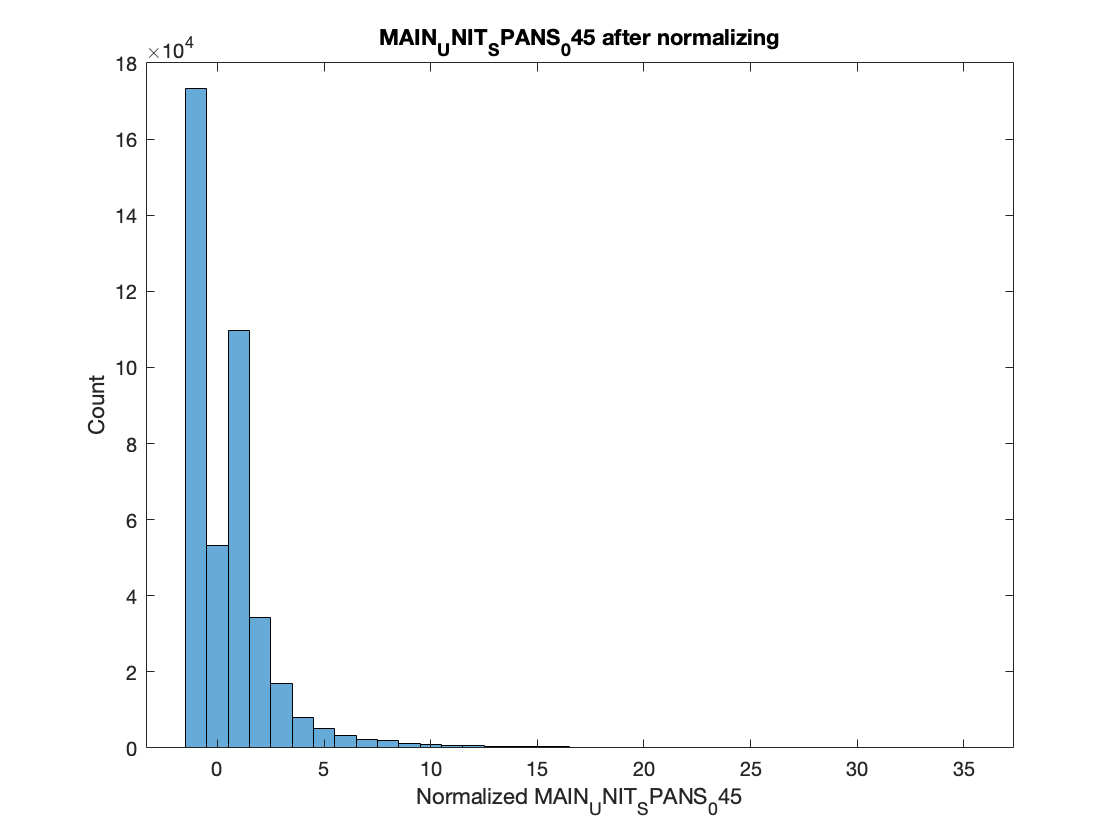

NBI2020_updated.MAIN_UNIT_SPANS_045 = normalize(NBI2020_updated.MAIN_UNIT_SPANS_045,"zscore","robust");
histogram(NBI2020_updated.MAIN_UNIT_SPANS_045)
xlabel("Normalized MAIN_UNIT_SPANS_045")
ylabel("Count")
title("MAIN_UNIT_SPANS_045 after normalizing")

2.4 APPR_SPANS_046 numeric

recognize outlier

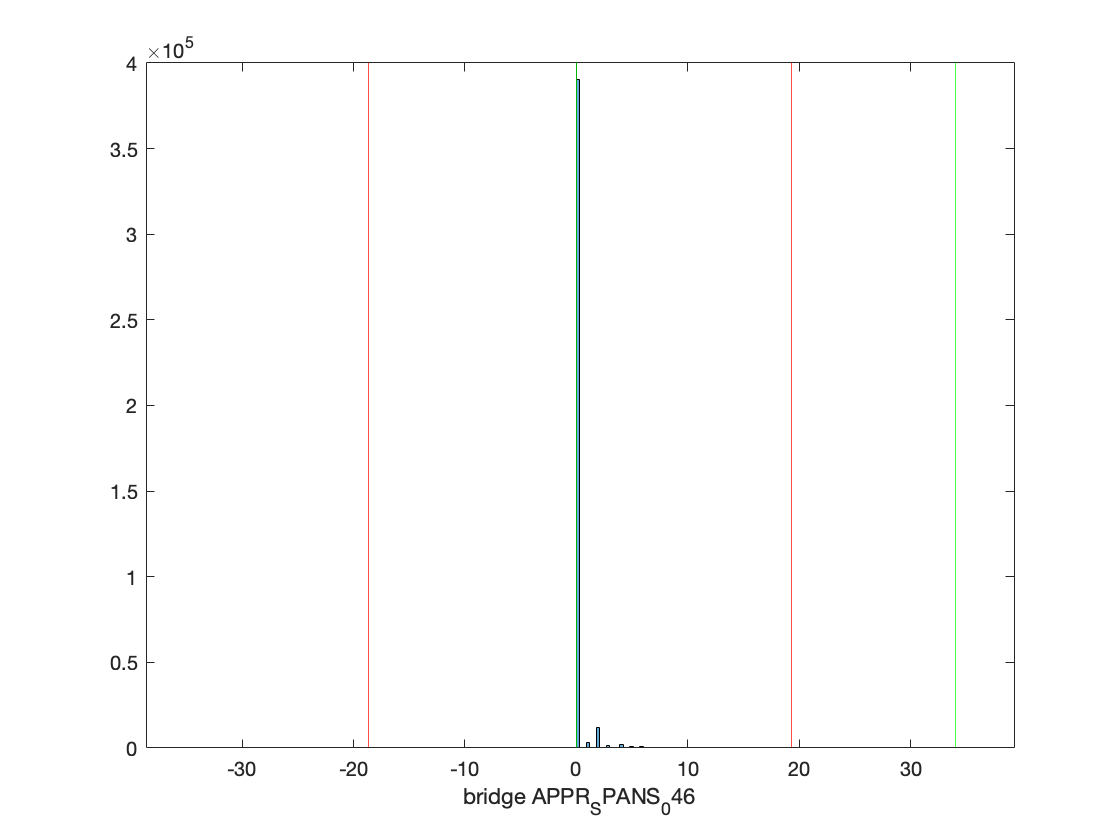

% using four methods to recognize outliers for a specific feature
[~,stdLow,stdHigh,~] = isoutlier(NBI2020_updated.APPR_SPANS_046,"mean");  
[~,quartLow,quartHigh,~] = isoutlier(NBI2020_updated.APPR_SPANS_046,"quartiles");  
[~,medLow,medHigh,~] = isoutlier(NBI2020_updated.APPR_SPANS_046,"median","ThresholdFactor",5);
[~,pLow,pHigh,~] = isoutlier(NBI2020_updated.APPR_SPANS_046,"percentiles",[0,99.9]);  % choosing this method

histogram(NBI2020_updated.APPR_SPANS_046);  
xlabel("bridge APPR_SPANS_046"); 
xline(stdLow,"r"); xline(stdHigh,"r"); 
xline(quartLow,"b"); xline(quartHigh,"b"); 
xline(medLow,"k"); xline(medHigh,"k");  
xline(pLow,"g"); xline(pHigh,"g")

xlim([stdLow-20,stdHigh+20]) %optical zoom in

remove outliers

h_before = height(NBI2020_updated)

h_before = 414595

NBI2020_updated = rmoutliers(NBI2020_updated,"percentiles",[0,99.9],"DataVariables","APPR_SPANS_046");
h_after = height(NBI2020_updated)

h_after = 414189

h_removed = h_before - h_after

h_removed = 406

normalizing

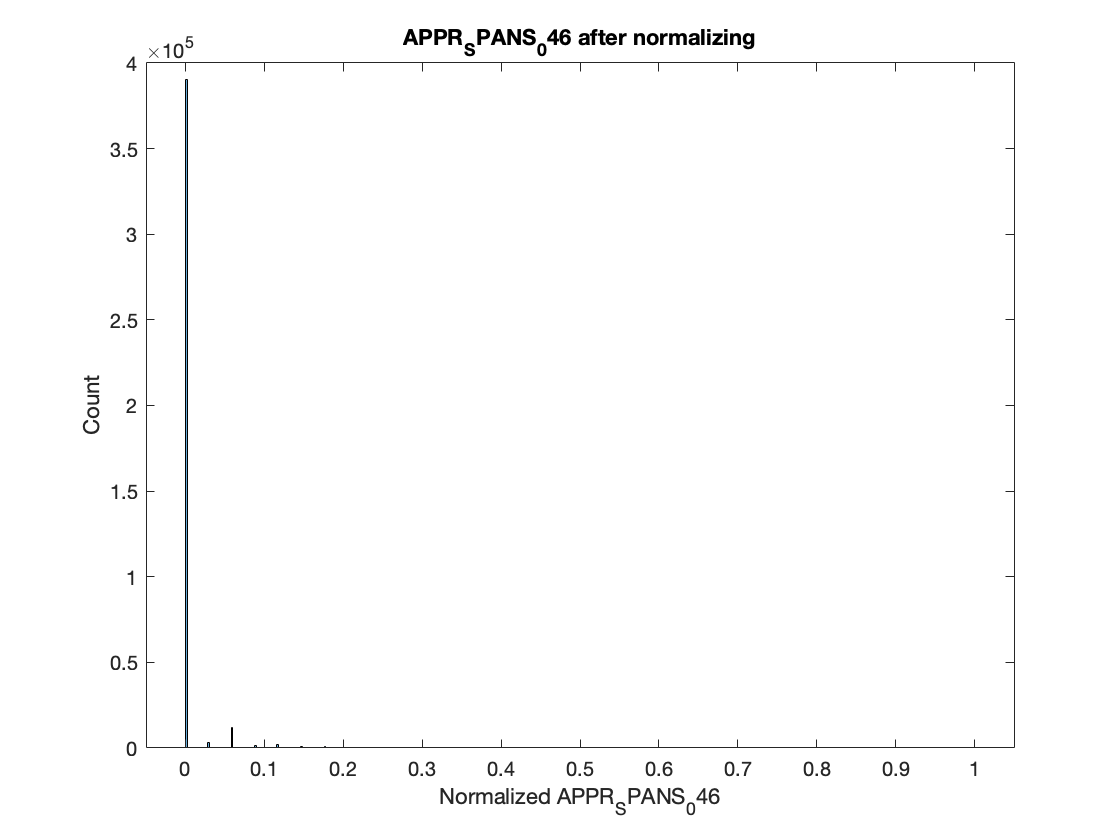

NBI2020_updated.APPR_SPANS_046 = normalize(NBI2020_updated.APPR_SPANS_046,"range");
histogram(NBI2020_updated.APPR_SPANS_046)
xlabel("Normalized APPR_SPANS_046")
ylabel("Count")
title("APPR_SPANS_046 after normalizing")

2.5 MAX_SPAN_LEN_MT_048 numeric

recognize outlier

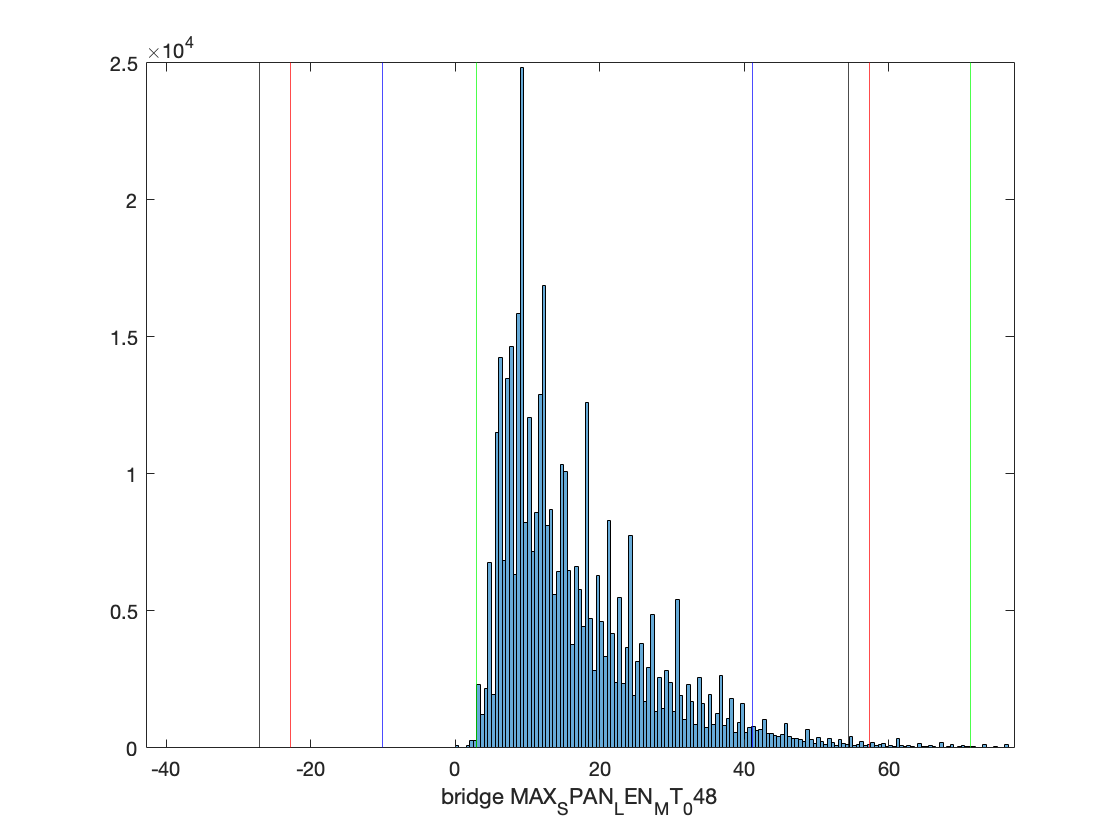

% using four methods to recognize outliers for a specific feature
[~,stdLow,stdHigh,~] = isoutlier(NBI2020_updated.MAX_SPAN_LEN_MT_048,"mean");  
[~,quartLow,quartHigh,~] = isoutlier(NBI2020_updated.MAX_SPAN_LEN_MT_048,"quartiles");  
[~,medLow,medHigh,~] = isoutlier(NBI2020_updated.MAX_SPAN_LEN_MT_048,"median","ThresholdFactor",5);
[~,pLow,pHigh,~] = isoutlier(NBI2020_updated.MAX_SPAN_LEN_MT_048,"percentiles",[0.5,99.5]);  % choosing this method

histogram(NBI2020_updated.MAX_SPAN_LEN_MT_048);  
xlabel("bridge MAX_SPAN_LEN_MT_048"); 
xline(stdLow,"r"); xline(stdHigh,"r"); 
xline(quartLow,"b"); xline(quartHigh,"b"); 
xline(medLow,"k"); xline(medHigh,"k");  
xline(pLow,"g"); xline(pHigh,"g")

xlim([stdLow-20,stdHigh+20]) %optical zoom in

remove outliers

h_before = height(NBI2020_updated)

h_before = 414189

NBI2020_updated = rmoutliers(NBI2020_updated,"percentiles",[0.5,99.5],"DataVariables","MAX_SPAN_LEN_MT_048");
h_after = height(NBI2020_updated)

h_after = 411340

h_removed = h_before - h_after

h_removed = 2849

normalizing

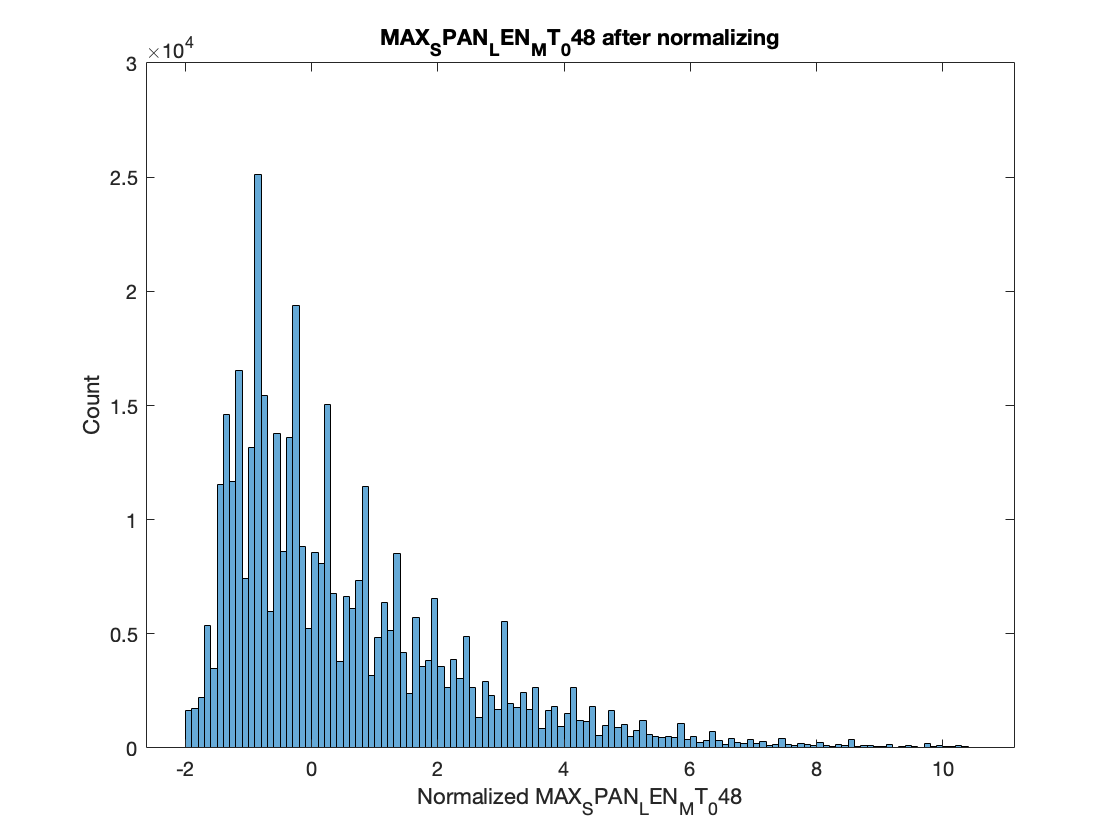

NBI2020_updated.MAX_SPAN_LEN_MT_048 = normalize(NBI2020_updated.MAX_SPAN_LEN_MT_048,"zscore","robust");
histogram(NBI2020_updated.MAX_SPAN_LEN_MT_048)
xlabel("Normalized MAX_SPAN_LEN_MT_048")
ylabel("Count")
title("MAX_SPAN_LEN_MT_048 after normalizing")

2.6 STRUCTURE_LEN_MT_049 numeric

recognize outlier

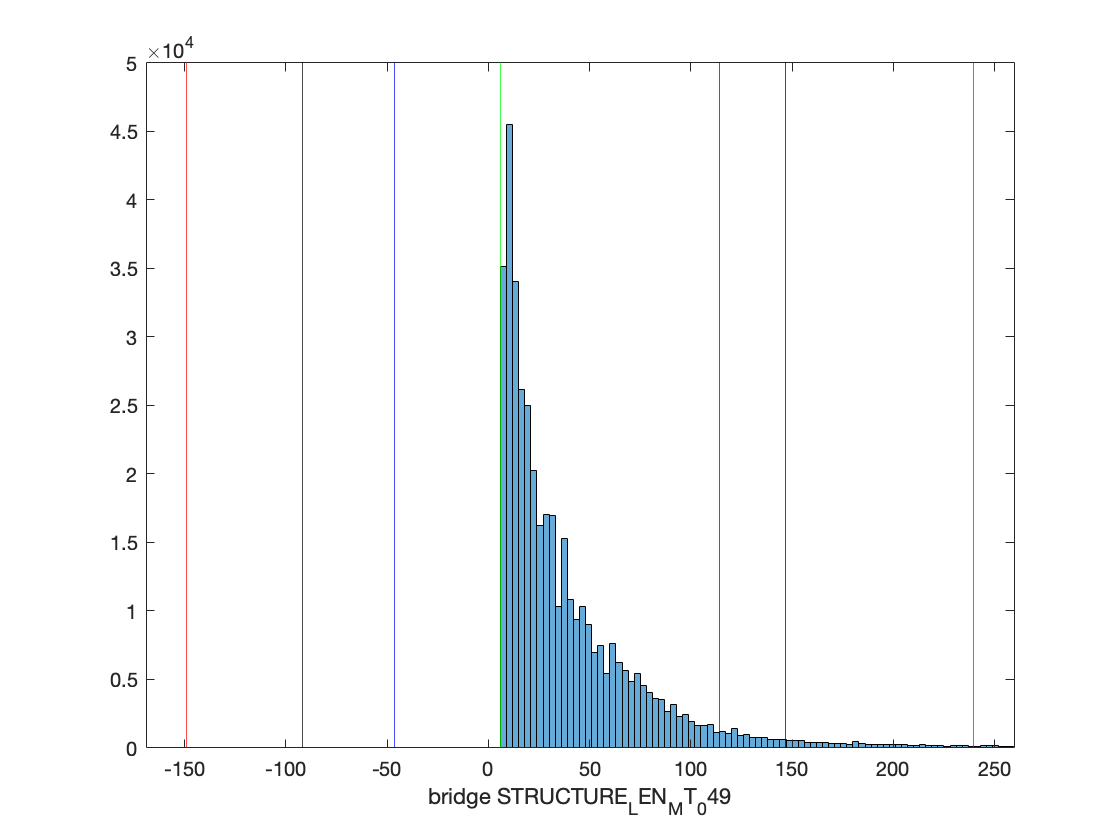

% using four methods to recognize outliers for a specific feature
[~,stdLow,stdHigh,~] = isoutlier(NBI2020_updated.STRUCTURE_LEN_MT_049,"mean");  
[~,quartLow,quartHigh,~] = isoutlier(NBI2020_updated.STRUCTURE_LEN_MT_049,"quartiles");  
[~,medLow,medHigh,~] = isoutlier(NBI2020_updated.STRUCTURE_LEN_MT_049,"median","ThresholdFactor",5);
[~,pLow,pHigh,~] = isoutlier(NBI2020_updated.STRUCTURE_LEN_MT_049,"percentiles",[0,99]);  % choosing this method

histogram(NBI2020_updated.STRUCTURE_LEN_MT_049);  
xlabel("bridge STRUCTURE_LEN_MT_049"); 
xline(stdLow,"r"); xline(stdHigh,"r"); 
xline(quartLow,"b"); xline(quartHigh,"b"); 
xline(medLow,"k"); xline(medHigh,"k");  
xline(pLow,"g"); xline(pHigh,"g")

xlim([stdLow-20,stdHigh+20]) %optical zoom in

remove outliers

h_before = height(NBI2020_updated)

h_before = 411340

NBI2020_updated = rmoutliers(NBI2020_updated,"percentiles",[0,99],"DataVariables","STRUCTURE_LEN_MT_049");
h_after = height(NBI2020_updated)

h_after = 407228

h_removed = h_before - h_after

h_removed = 4112

normalizing

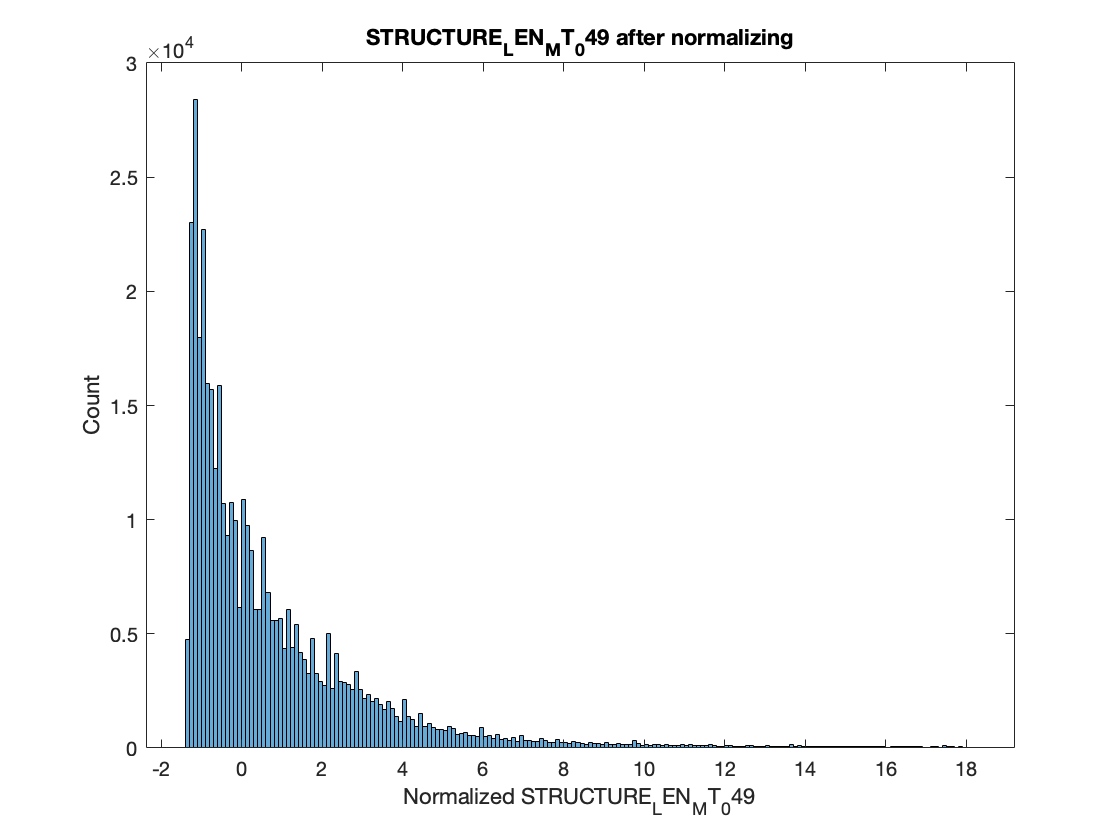

NBI2020_updated.STRUCTURE_LEN_MT_049 = normalize(NBI2020_updated.STRUCTURE_LEN_MT_049,"zscore","robust");
histogram(NBI2020_updated.STRUCTURE_LEN_MT_049)
xlabel("Normalized STRUCTURE_LEN_MT_049")
ylabel("Count")
title("STRUCTURE_LEN_MT_049 after normalizing")

2.7 ROADWAY_WIDTH_MT_051 numeric

recognize outlier

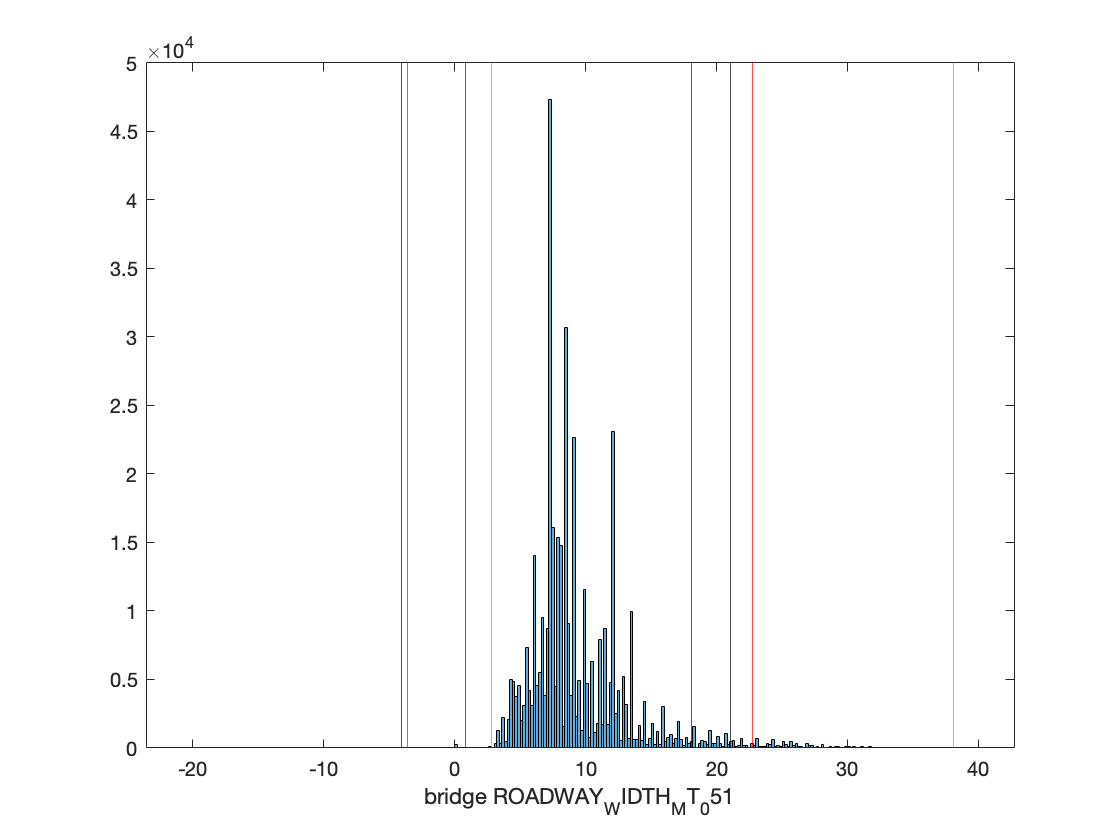

% using four methods to recognize outliers for a specific feature
[~,stdLow,stdHigh,~] = isoutlier(NBI2020_updated.ROADWAY_WIDTH_MT_051,"mean");  
[~,quartLow,quartHigh,~] = isoutlier(NBI2020_updated.ROADWAY_WIDTH_MT_051,"quartiles");  
[~,medLow,medHigh,~] = isoutlier(NBI2020_updated.ROADWAY_WIDTH_MT_051,"median","ThresholdFactor",5);
[~,pLow,pHigh,~] = isoutlier(NBI2020_updated.ROADWAY_WIDTH_MT_051,"percentiles",[0.1,99.9]);  % choosing this method

histogram(NBI2020_updated.ROADWAY_WIDTH_MT_051);  
xlabel("bridge ROADWAY_WIDTH_MT_051"); 
xline(stdLow,"r"); xline(stdHigh,"r"); 
xline(quartLow,"b"); xline(quartHigh,"b"); 
xline(medLow,"k"); xline(medHigh,"k");  
xline(pLow,"g"); xline(pHigh,"g")

xlim([stdLow-20,stdHigh+20]) %optical zoom in

remove outliers

h_before = height(NBI2020_updated)

h_before = 407228

NBI2020_updated = rmoutliers(NBI2020_updated,"percentiles",[0.1,99.9],"DataVariables","ROADWAY_WIDTH_MT_051");
h_after = height(NBI2020_updated)

h_after = 406430

h_removed = h_before - h_after

h_removed = 798

normalizing

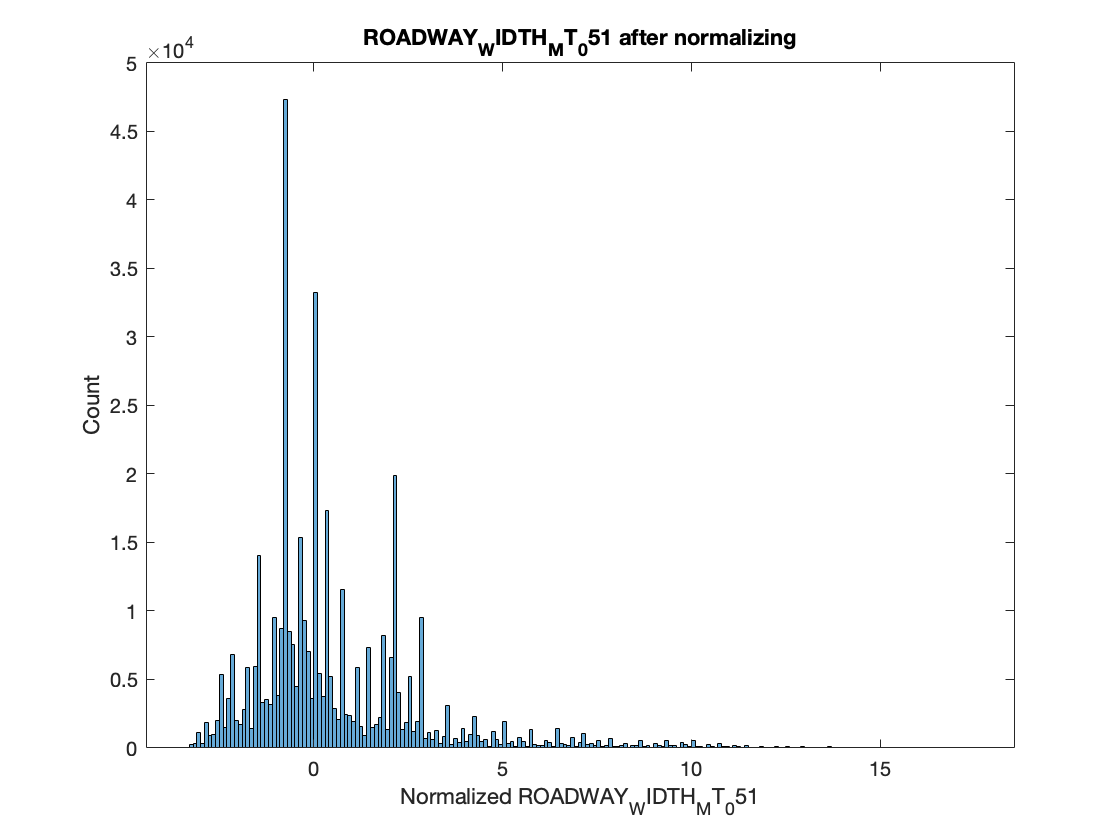

NBI2020_updated.ROADWAY_WIDTH_MT_051 = normalize(NBI2020_updated.ROADWAY_WIDTH_MT_051,"zscore","robust");
histogram(NBI2020_updated.ROADWAY_WIDTH_MT_051)
xlabel("Normalized ROADWAY_WIDTH_MT_051")
ylabel("Count")
title("ROADWAY_WIDTH_MT_051 after normalizing")

2.8 DECK_WIDTH_MT_052 numeric

recognize outlier

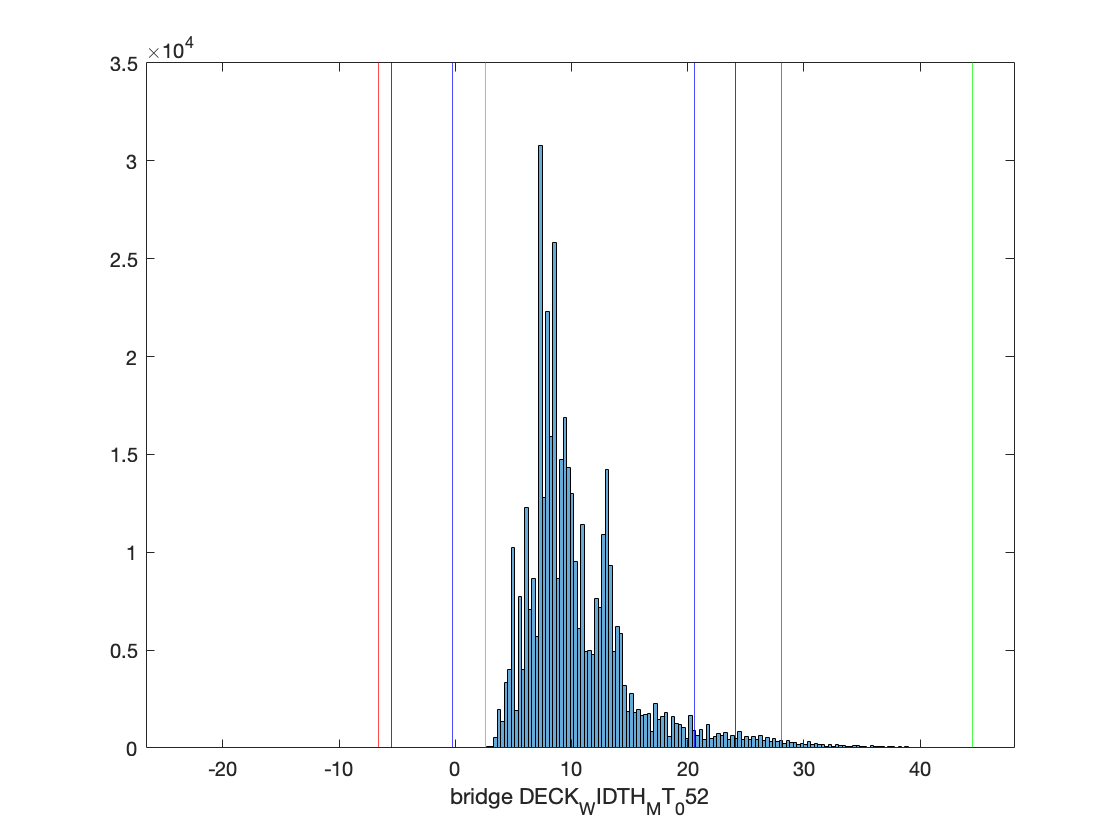

% using four methods to recognize outliers for a specific feature
[~,stdLow,stdHigh,~] = isoutlier(NBI2020_updated.DECK_WIDTH_MT_052,"mean");  
[~,quartLow,quartHigh,~] = isoutlier(NBI2020_updated.DECK_WIDTH_MT_052,"quartiles");  
[~,medLow,medHigh,~] = isoutlier(NBI2020_updated.DECK_WIDTH_MT_052,"median","ThresholdFactor",5);
[~,pLow,pHigh,~] = isoutlier(NBI2020_updated.DECK_WIDTH_MT_052,"percentiles",[0.01,99.9]);  % choosing this method

histogram(NBI2020_updated.DECK_WIDTH_MT_052);  
xlabel("bridge DECK_WIDTH_MT_052"); 
xline(stdLow,"r"); xline(stdHigh,"r"); 
xline(quartLow,"b"); xline(quartHigh,"b"); 
xline(medLow,"k"); xline(medHigh,"k");  
xline(pLow,"g"); xline(pHigh,"g")

xlim([stdLow-20,stdHigh+20]) %optical zoom in

remove outliers

h_before = height(NBI2020_updated)

h_before = 406430

NBI2020_updated = rmoutliers(NBI2020_updated,"percentiles",[0.01,99.9],"DataVariables","DECK_WIDTH_MT_052");
h_after = height(NBI2020_updated)

h_after = 405984

h_removed = h_before - h_after

h_removed = 446

normalizing

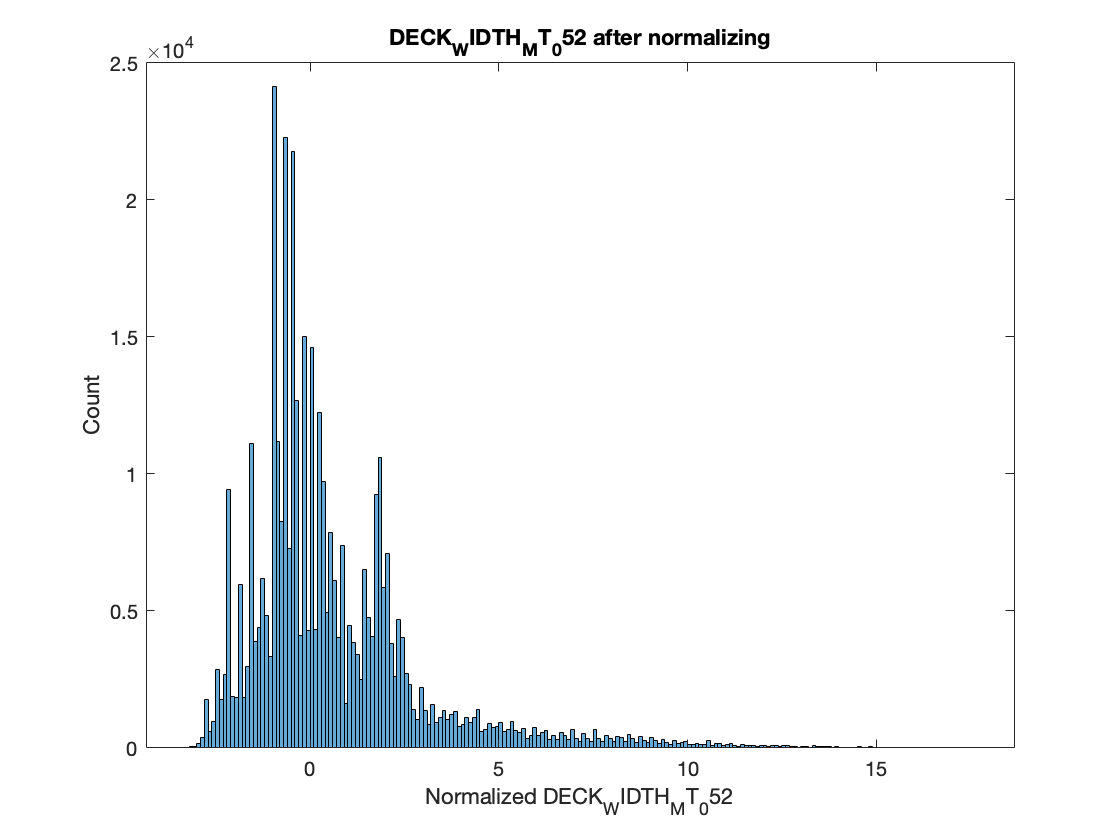

NBI2020_updated.DECK_WIDTH_MT_052 = normalize(NBI2020_updated.DECK_WIDTH_MT_052,"zscore","robust");
histogram(NBI2020_updated.DECK_WIDTH_MT_052)
xlabel("Normalized DECK_WIDTH_MT_052")
ylabel("Count")
title("DECK_WIDTH_MT_052 after normalizing")

## section 3 recorgnize/remove outliers and normalize nominal features

3.1 OWNER_022 feature -- nominal

recognize outliers

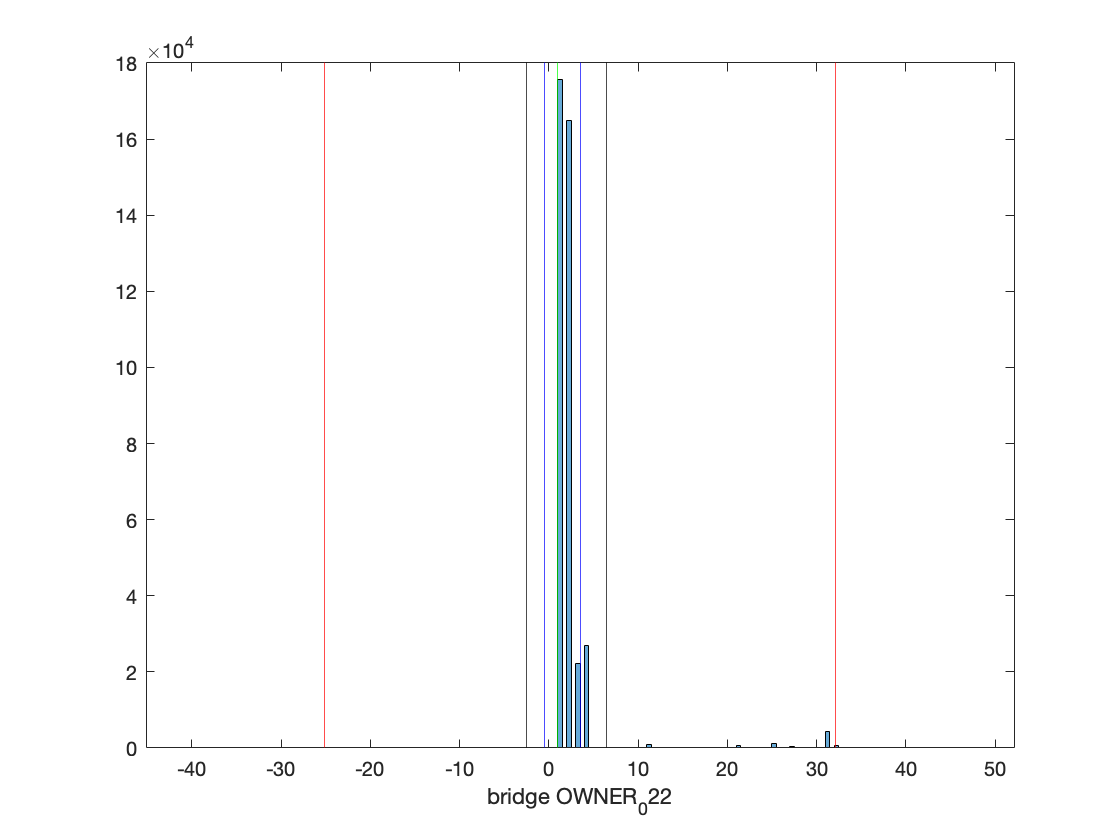

% using four methods to recognize outliers for a specific feature
[~,stdLow,stdHigh,~] = isoutlier(NBI2020_updated.OWNER_022,"mean");  
[~,quartLow,quartHigh,~] = isoutlier(NBI2020_updated.OWNER_022,"quartiles");  
[~,medLow,medHigh,~] = isoutlier(NBI2020_updated.OWNER_022,"median");
[~,pLow,pHigh,~] = isoutlier(NBI2020_updated.OWNER_022,"percentiles",[0,99]);

histogram(NBI2020_updated.OWNER_022);  
xlabel("bridge OWNER_022"); 
xline(stdLow,"r"); xline(stdHigh,"r"); 
xline(quartLow,"b"); xline(quartHigh,"b"); 
xline(medLow,"k"); xline(medHigh,"k");  % 
xline(pLow,"g"); xline(pHigh,"g")

xlim([stdLow-20,stdHigh+20]) %optical zoom in

removing recognized outliers -- using MAD method

h_before = height(NBI2020_updated)

h_before = 405984

NBI2020_updated = rmoutliers(NBI2020_updated,"median","DataVariables","OWNER_022");
h_after = height(NBI2020_updated)

h_after = 389644

h_removed = h_before - h_after  % number of samples removed in this step

h_removed = 16340

3.2 FUNCTIONAL_CLASS_026 feature -- 

recognize outliers

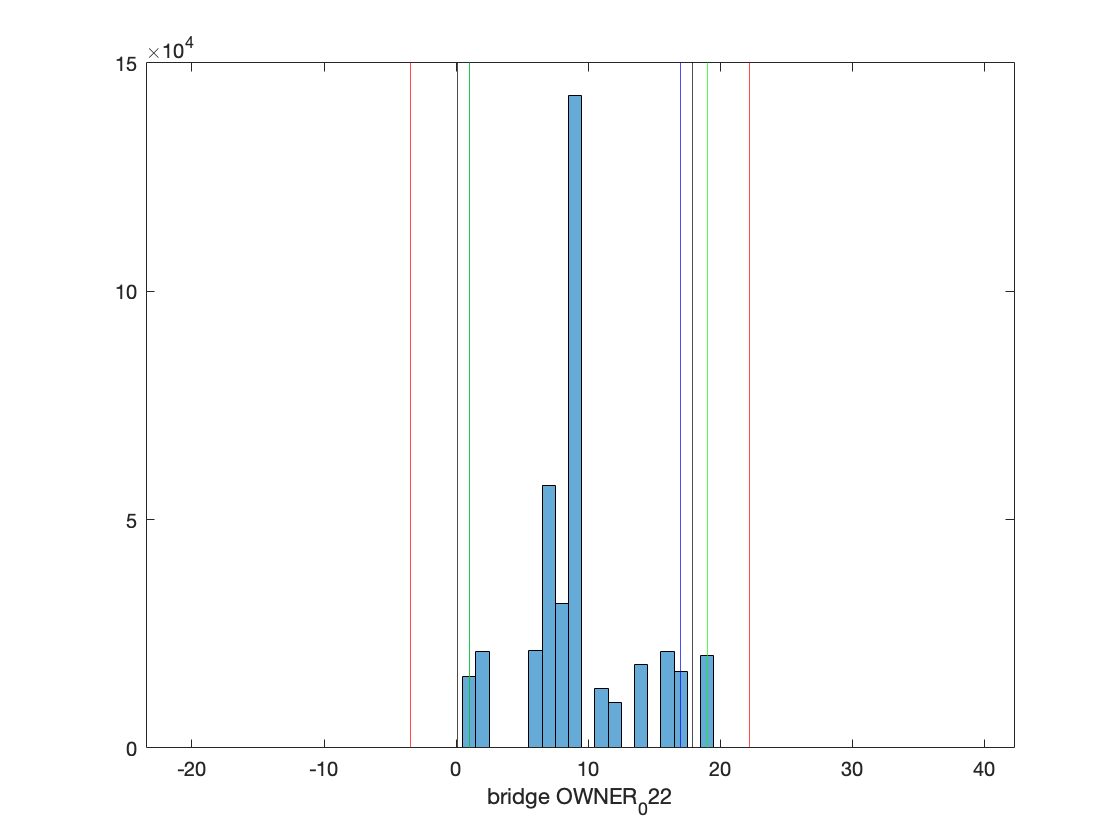

% using four methods to recognize outliers for a specific feature
[~,stdLow,stdHigh,~] = isoutlier(NBI2020_updated.FUNCTIONAL_CLASS_026,"mean");  
[~,quartLow,quartHigh,~] = isoutlier(NBI2020_updated.FUNCTIONAL_CLASS_026,"quartiles");  
[~,medLow,medHigh,~] = isoutlier(NBI2020_updated.FUNCTIONAL_CLASS_026,"median");
[~,pLow,pHigh,~] = isoutlier(NBI2020_updated.FUNCTIONAL_CLASS_026,"percentiles",[0,99]);

histogram(NBI2020_updated.FUNCTIONAL_CLASS_026);  
xlabel("bridge OWNER_022"); 
xline(stdLow,"r"); xline(stdHigh,"r"); 
xline(quartLow,"b"); xline(quartHigh,"b"); 
xline(medLow,"k"); xline(medHigh,"k");  % 
xline(pLow,"g"); xline(pHigh,"g")

xlim([stdLow-20,stdHigh+20]) %optical zoom in

reduce categorical levels -- similar level into similar groups

group functional class into 4 levels: rural pricipal class, rural other classes, urban principal class, urban other classes.

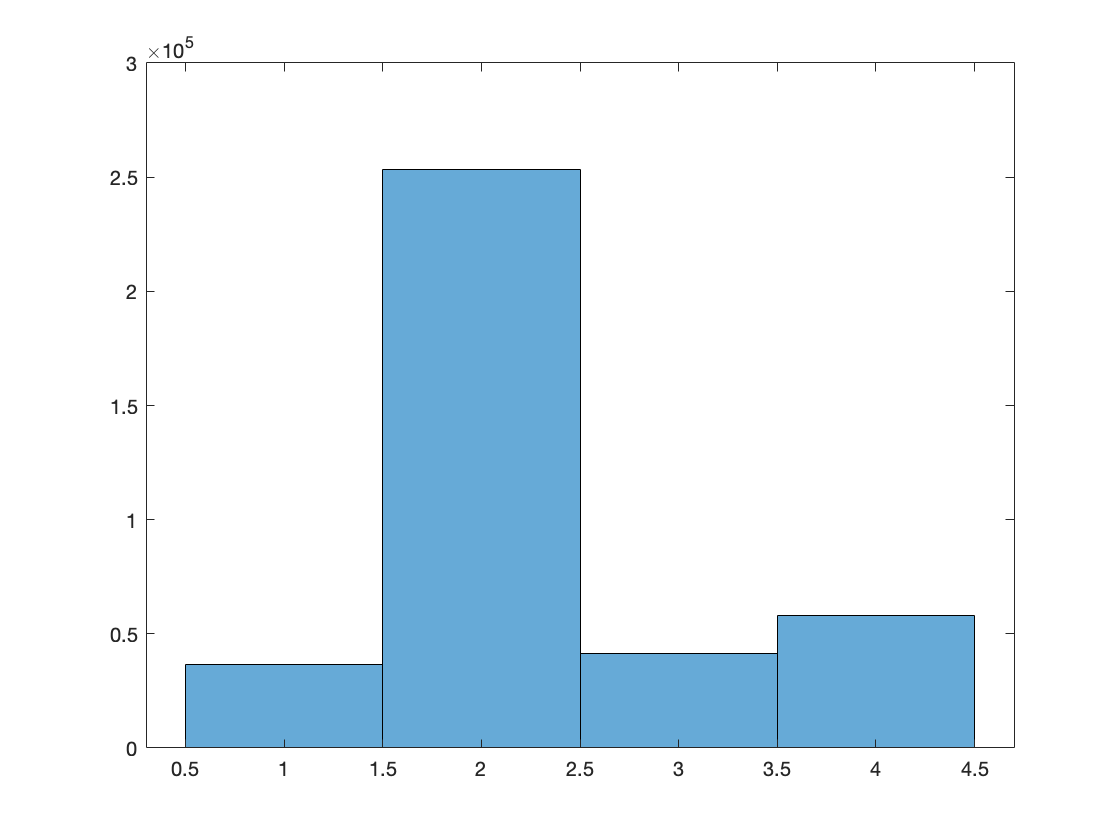

NBI2020_updated_temp = NBI2020_updated;  % create a temperal table to re-code function class feature.
NBI2020_updated_temp.FUNCTIONAL_CLASS_026(NBI2020_updated_temp.FUNCTIONAL_CLASS_026 == 1 | ...
    NBI2020_updated_temp.FUNCTIONAL_CLASS_026 == 2) = 1;
NBI2020_updated_temp.FUNCTIONAL_CLASS_026(NBI2020_updated_temp.FUNCTIONAL_CLASS_026 == 6 | ...
    NBI2020_updated_temp.FUNCTIONAL_CLASS_026 == 7 |...
    NBI2020_updated_temp.FUNCTIONAL_CLASS_026 == 8 |...
    NBI2020_updated_temp.FUNCTIONAL_CLASS_026 == 9) = 2;
NBI2020_updated_temp.FUNCTIONAL_CLASS_026(NBI2020_updated_temp.FUNCTIONAL_CLASS_026 == 11 | ...
    NBI2020_updated_temp.FUNCTIONAL_CLASS_026 == 12 |...
    NBI2020_updated_temp.FUNCTIONAL_CLASS_026 == 14) = 3;
NBI2020_updated_temp.FUNCTIONAL_CLASS_026(NBI2020_updated_temp.FUNCTIONAL_CLASS_026 == 16 | ...
    NBI2020_updated_temp.FUNCTIONAL_CLASS_026 == 17 |...
    NBI2020_updated_temp.FUNCTIONAL_CLASS_026 == 19) = 4;
histogram(NBI2020_updated_temp.FUNCTIONAL_CLASS_026)

NBI2020_updated = NBI2020_updated_temp;  % assign revised temporal table back to the original table.

3.3 DESIGN_LOAD_031 -- ordinal variable

recognize outliers

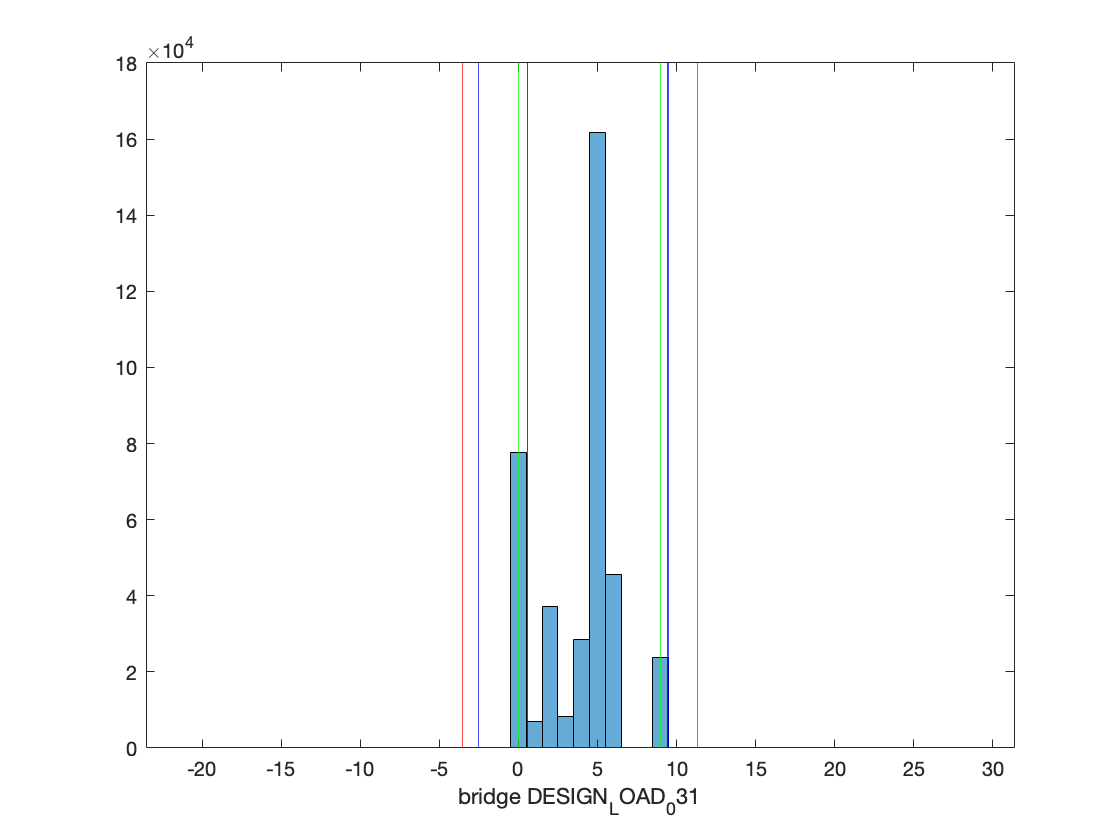

% using four methods to recognize outliers for a specific feature
[~,stdLow,stdHigh,~] = isoutlier(NBI2020_updated.DESIGN_LOAD_031,"mean");  
[~,quartLow,quartHigh,~] = isoutlier(NBI2020_updated.DESIGN_LOAD_031,"quartiles");  
[~,medLow,medHigh,~] = isoutlier(NBI2020_updated.DESIGN_LOAD_031,"median");  % choosing median method
[~,pLow,pHigh,~] = isoutlier(NBI2020_updated.DESIGN_LOAD_031,"percentiles",[0,99]);

histogram(NBI2020_updated.DESIGN_LOAD_031);  
xlabel("bridge DESIGN_LOAD_031"); 
xline(stdLow,"r"); xline(stdHigh,"r"); 
xline(quartLow,"b"); xline(quartHigh,"b"); 
xline(medLow,"k"); xline(medHigh,"k");  % 
xline(pLow,"g"); xline(pHigh,"g")

xlim([stdLow-20,stdHigh+20]) %optical zoom in

removing recognized outliers -- using MAD method

h_before = height(NBI2020_updated)

h_before = 389644

NBI2020_updated_1 = NBI2020_updated;
NBI2020_updated_1 = NBI2020_updated_1(NBI2020_updated_1.DESIGN_LOAD_031 ~= 7,:);
NBI2020_updated_1 = NBI2020_updated_1(NBI2020_updated_1.DESIGN_LOAD_031 ~= 8,:);  % remove pedestrian and railroad design loads coded as '7' and '8'.
NBI2020_updated_1.DESIGN_LOAD_031(NBI2020_updated_1.DESIGN_LOAD_031 == 9) = 7;
NBI2020_updated_1 = rmoutliers(NBI2020_updated_1,"median","DataVariables","DESIGN_LOAD_031");
h_after = height(NBI2020_updated_1)

h_after = 311957

h_removed = h_before - h_after  % number of samples removed in this step

h_removed = 77687

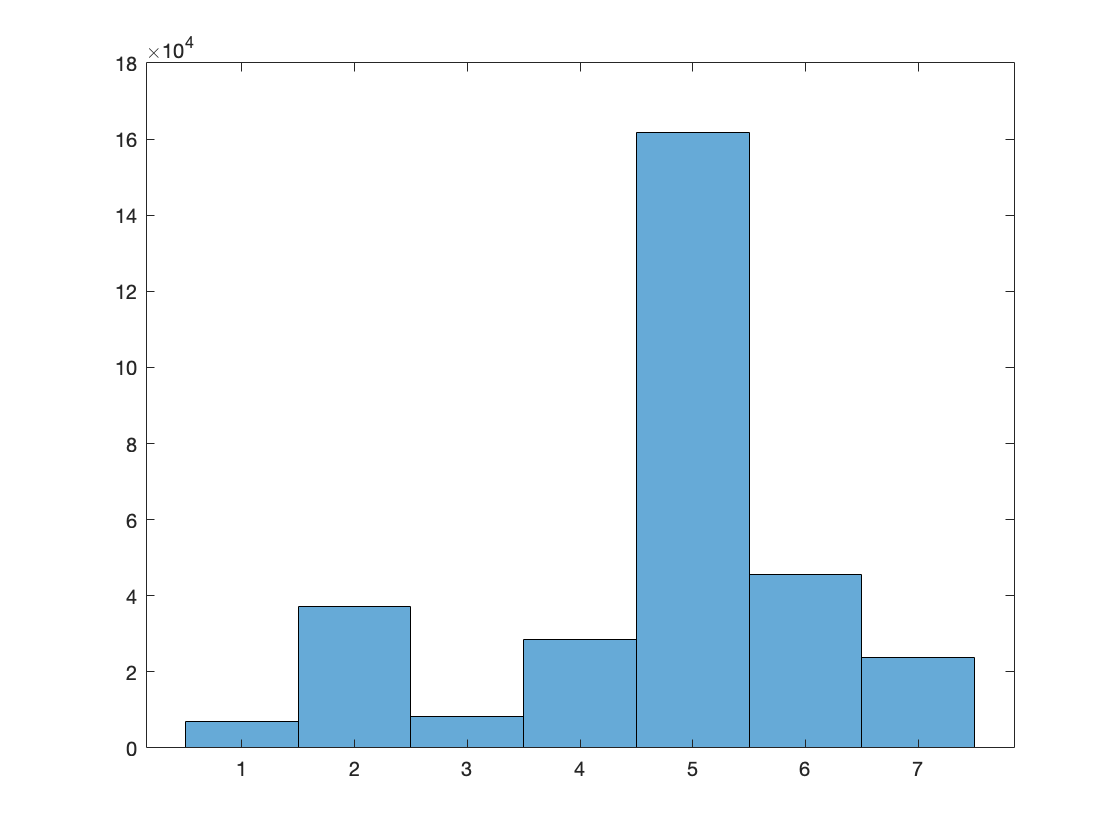

histogram(NBI2020_updated_1.DESIGN_LOAD_031)

normalizing

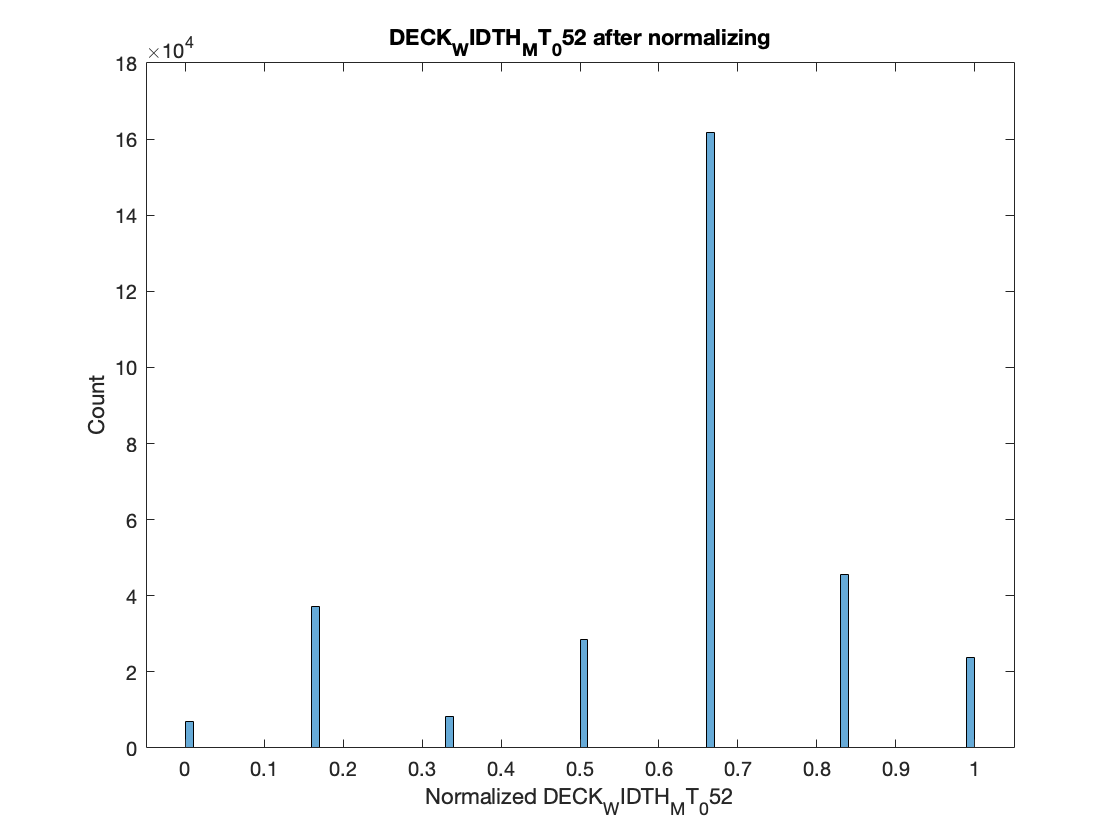

NBI2020_updated_1.DESIGN_LOAD_031 = normalize(NBI2020_updated_1.DESIGN_LOAD_031,"range");
histogram(NBI2020_updated_1.DESIGN_LOAD_031)
xlabel("Normalized DECK_WIDTH_MT_052")
ylabel("Count")
title("DECK_WIDTH_MT_052 after normalizing")


NBI2020_updated = NBI2020_updated_1;  % put temporal talbe NBI2020_updated_1 back to NBI2020_updated table.

3.4 SERVICE_UND_042B -- nominal variable

recognize outliers

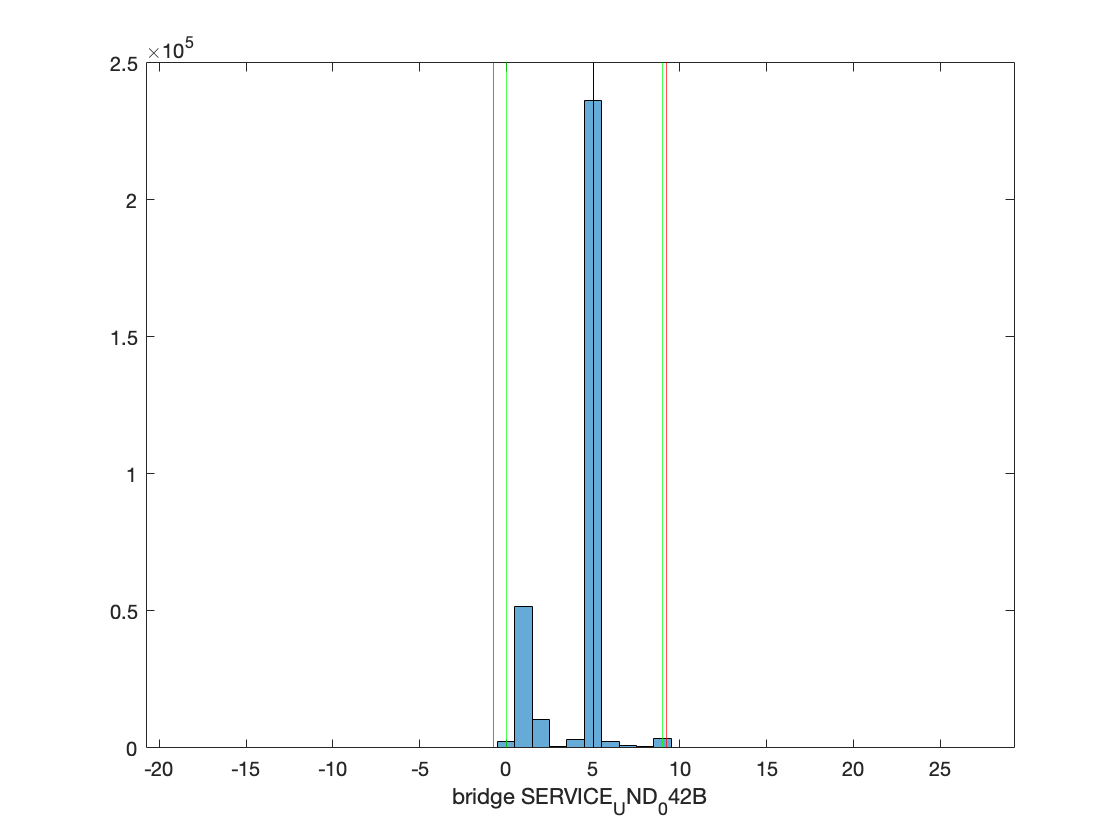

% using four methods to recognize outliers for a specific feature
[~,stdLow,stdHigh,~] = isoutlier(NBI2020_updated.SERVICE_UND_042B,"mean");  
[~,quartLow,quartHigh,~] = isoutlier(NBI2020_updated.SERVICE_UND_042B,"quartiles");  
[~,medLow,medHigh,~] = isoutlier(NBI2020_updated.SERVICE_UND_042B,"median");  % choosing median method
[~,pLow,pHigh,~] = isoutlier(NBI2020_updated.SERVICE_UND_042B,"percentiles",[0,99]);

histogram(NBI2020_updated.SERVICE_UND_042B);  
xlabel("bridge SERVICE_UND_042B"); 
xline(stdLow,"r"); xline(stdHigh,"r"); 
xline(quartLow,"b"); xline(quartHigh,"b"); 
xline(medLow,"k"); xline(medHigh,"k");  % 
xline(pLow,"g"); xline(pHigh,"g")

xlim([stdLow-20,stdHigh+20]) %optical zoom in

reduce categorical levels

group types of service under bridges into three groups: highway only, railway only, waterway only, others. (1,2,3,4)

NBI2020_updated_temp = NBI2020_updated;
h_before = height(NBI2020_updated_temp)

h_before = 311957

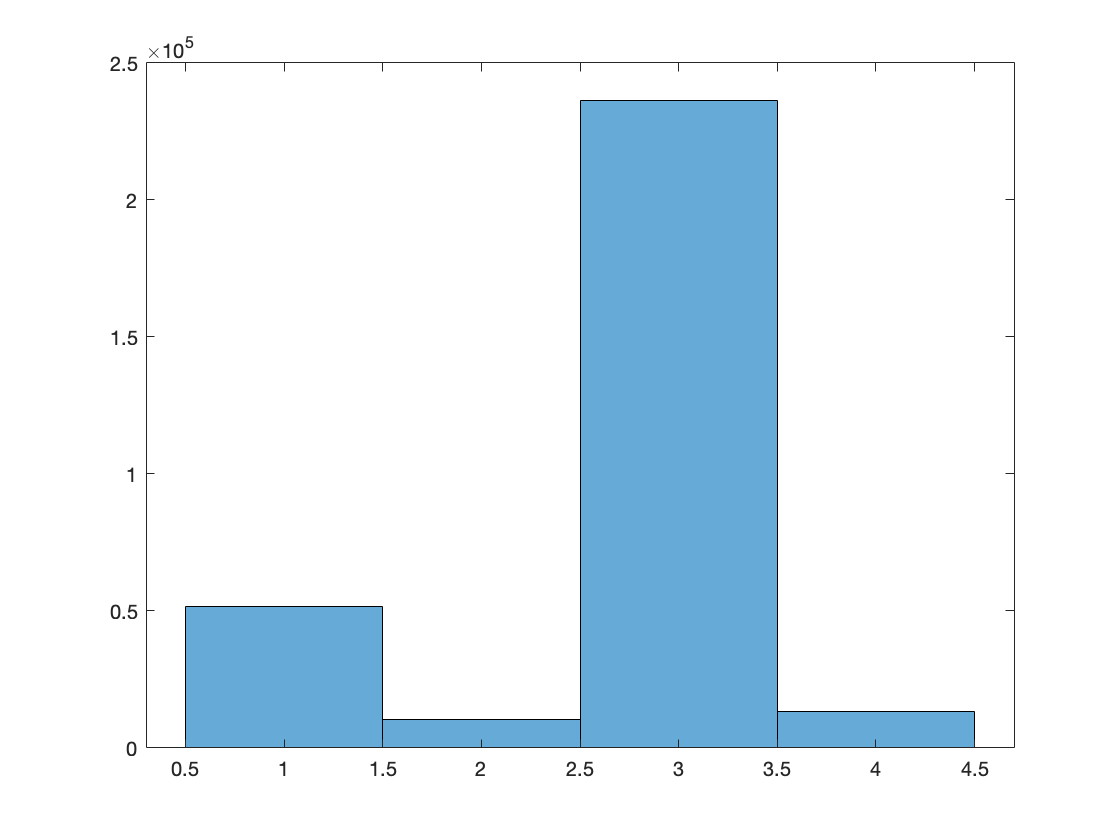

NBI2020_updated_temp.SERVICE_UND_042B(NBI2020_updated_temp.SERVICE_UND_042B ~= 1 & ...
    NBI2020_updated_temp.SERVICE_UND_042B ~= 2 & ...
    NBI2020_updated_temp.SERVICE_UND_042B ~= 5) = 4;  % encodes bridges into 'others'.
NBI2020_updated_temp.SERVICE_UND_042B(NBI2020_updated_temp.SERVICE_UND_042B == 5) = 3;  % encode 'waterway only'.
histogram(NBI2020_updated_temp.SERVICE_UND_042B)

h_after = height(NBI2020_updated_temp)

h_after = 311957

h_removed = h_before - h_after

h_removed = 0


NBI2020_updated = NBI2020_updated_temp;  % put revised table back to the original table.

3.5 STATE_CODE_001 -- nominal variable

recognize outliers

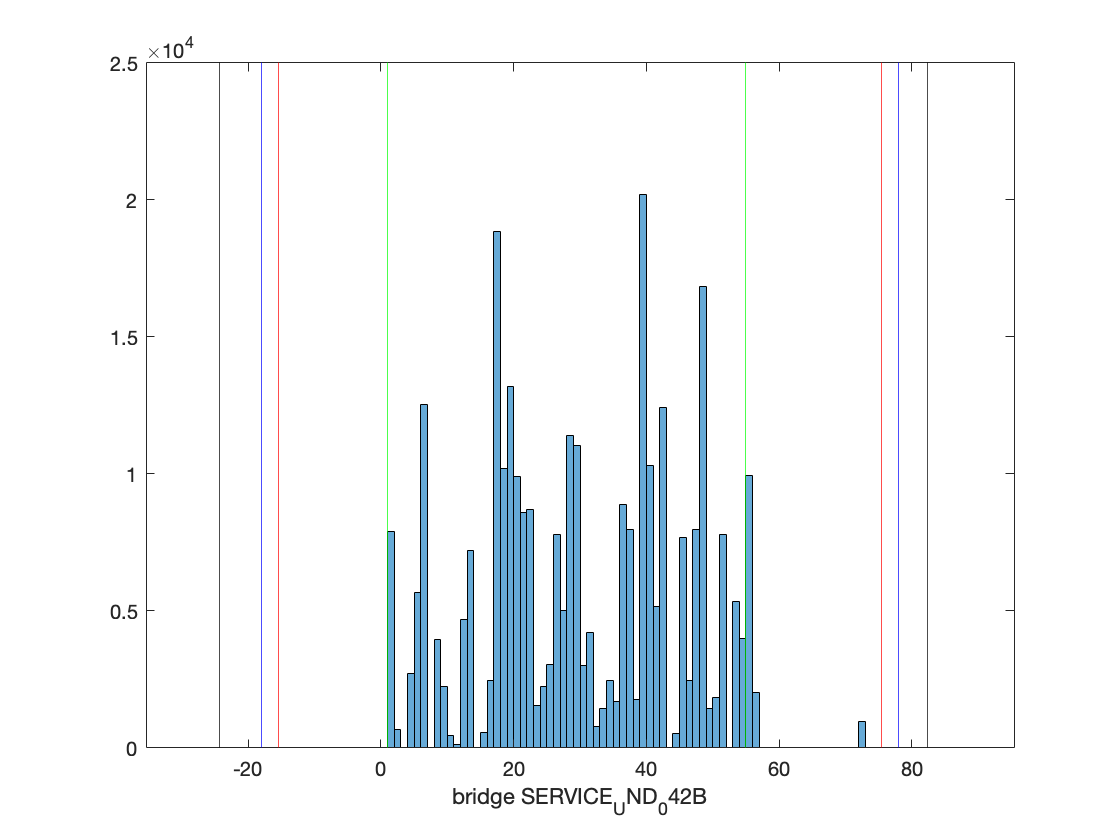

% using four methods to recognize outliers for a specific feature
[~,stdLow,stdHigh,~] = isoutlier(NBI2020_updated.STATE_CODE_001,"mean");  
[~,quartLow,quartHigh,~] = isoutlier(NBI2020_updated.STATE_CODE_001,"quartiles");  
[~,medLow,medHigh,~] = isoutlier(NBI2020_updated.STATE_CODE_001,"median");  % choosing median method
[~,pLow,pHigh,~] = isoutlier(NBI2020_updated.STATE_CODE_001,"percentiles",[0,99]);

histogram(NBI2020_updated.STATE_CODE_001);  
xlabel("bridge SERVICE_UND_042B"); 
xline(stdLow,"r"); xline(stdHigh,"r"); 
xline(quartLow,"b"); xline(quartHigh,"b"); 
xline(medLow,"k"); xline(medHigh,"k");  % 
xline(pLow,"g"); xline(pHigh,"g")

xlim([stdLow-20,stdHigh+20]) %optical zoom in

reducing cateorical level using sample frequency.

state_group = groupsummary(NBI2020_updated,"STATE_CODE_001")

state_group = 53×2 table
    STATE_CODE_001    GroupCount
    ______________    __________

           1             7885   
           2              663   
           4             2706   
           5             5667   
           6            12527   
           8             3955   
           9             2245   
          10              466   
          11              111   
          12             4692   
          13             7215   
          15              548   
          16             2479   
          17            18865   
          18            10201   
          19            13211   


state_sorted = sortrows(state_group,"GroupCount","descend")

state_sorted = 53×2 table
    STATE_CODE_001    GroupCount
    ______________    __________

          39            20202   
          17            18865   
          48            16825   
          19            13211   
           6            12527   
          42            12425   
          28            11418   
          29            11050   
          40            10322   
          18            10201   
          55             9949   
          20             9903   
          36             8876   
          22             8697   
          21             8581   
          47             7978   


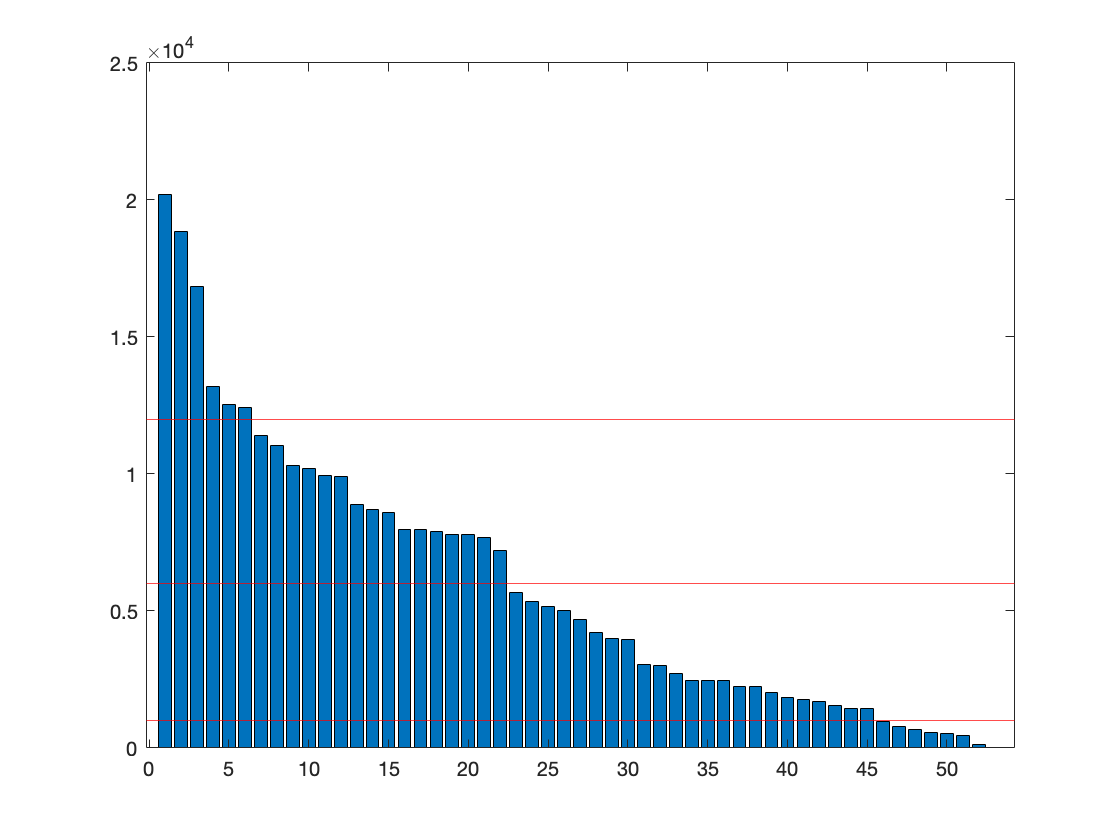

bar(state_sorted.GroupCount)
yline(12000,"r");
yline(6000,"r");
yline(1000,"r");

based on the dustribution of bridge numbers of individual states, categorize states into four levels: <1000, 1000~6000, 6000~12000, >12000, coded as A,B,C,D

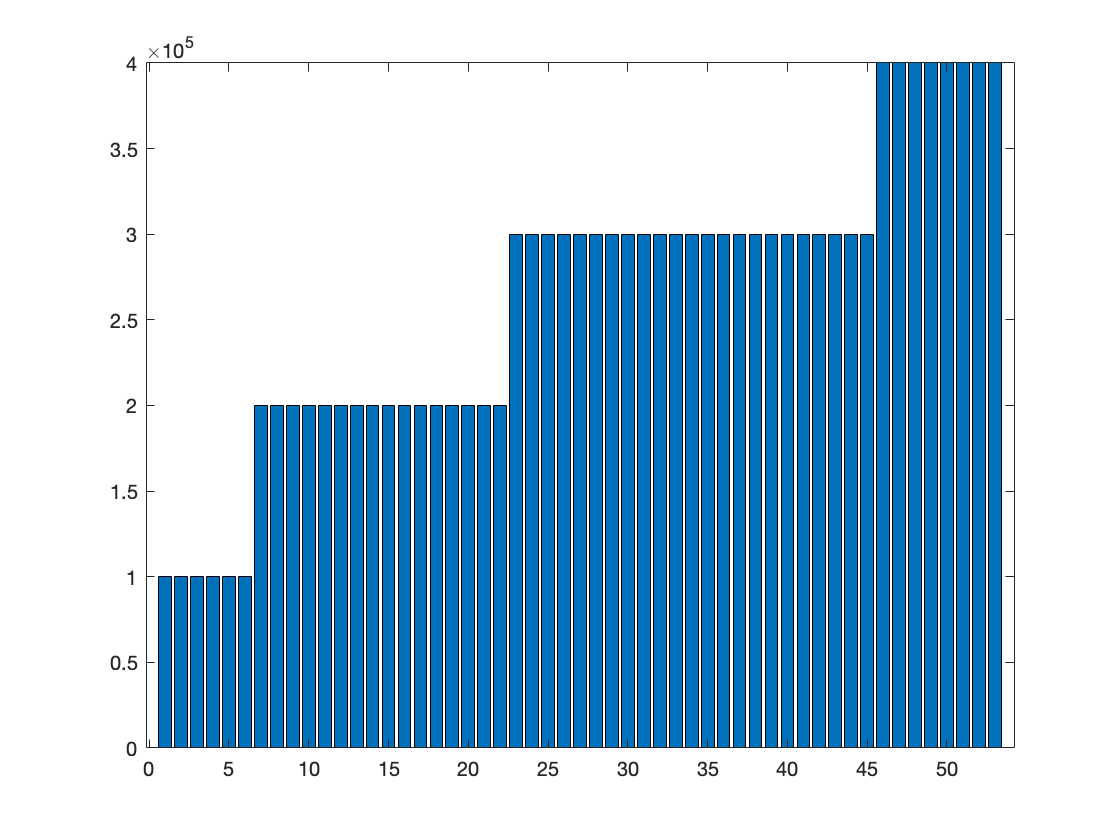

state_sorted.GroupCount(state_sorted.GroupCount >= 12000) = 100000;
state_sorted.GroupCount(state_sorted.GroupCount >= 6000 & state_sorted.GroupCount < 12000) = 200000;
state_sorted.GroupCount(state_sorted.GroupCount >= 1000 & state_sorted.GroupCount < 6000) = 300000;
state_sorted.GroupCount(state_sorted.GroupCount < 1000) = 400000;
bar(state_sorted.GroupCount)

NBI2020_updated_1 = NBI2020_updated;
NBI2020_updated_1 = innerjoin(state_sorted,NBI2020_updated_1);
NBI2020_updated_1 = removevars(NBI2020_updated_1,"STATE_CODE_001");  % remove old state codes
NBI2020_updated_1.Properties.VariableNames{'GroupCount'} = 'STATE_CODE_001';  % rename state codes.


## section 4 write revised tables into a txt file

writetable(NBI2020_updated_1, 'NBI2020.txt')